# axon_analysis_task_analysis_V1

% Axon analysis for TRAINING sessions of the square + reward task, aggregated with newAggregation/save_preprocessed.m
% (one Stimuli struct, 90 trials in 3 subsessions, single plane, 30 Hz). Same layout as axon_analysis_V3: checks first (PASS / WARN / FAIL),
% then the results for the selected ROIs. Run the sections in order; nothing is hard-coded to a frame rate, ROI count or trial number.
%
% Task (read from timed_Training.m and the stimulus log): wait 8-13 s (licking during the wait gives a time-out and a new wait), 2 s cyan square
% (lickWindowMax), 8.5 s grey (Tend). At level 1/2 with RewardDelay = 0 the pump TTL is sent by the stimulus PC right before the first square
% frame of EVERY trial, whether the mouse licks or not (timed_Training.m, 'send a TTL pulse to pump reward'). So square and reward start together:
% their onset responses cannot be told apart by timing. What the data do allow (and what this script tests):
%   - the onset response (square + reward delivery) against pseudo-onsets and against the arousal state,
%   - the CONSUMPTION of the reward: licking starts at a different latency on every trial (0.1 s to several s), so a response locked to the
%     first lick moves with that latency, a response locked to square/pump does not; the first lick bout after the reward is compared with
%     unrewarded spontaneous lick bouts in the wait period (same motor act, no reward),
%   - hit (lick inside the response window) against miss trials, and the change over the session,
%   - a cross-validated encoding model with onset, rewarded-bout, spontaneous-bout, lick-rate and arousal regressors (what does each add?).
% The reward is not logged. If the level or RewardDelay of another session is different, section 2 says so (reward_known).
%
% Layout:
%   Part A  necessary checks (text) + the session overview figure
%     0 settings | 1 load + integrity | 2 timing, sync, trial structure | 3 licks, behaviour, locomotion | 4 session overview |
%     5 ROI signal quality | 6 registration offset, FOV-wide events, drift, motion | 7 ROI selection
%   Part B  results for the selected ROIs (statistics on ROI-group means; the noise-like ROIs outside the selection are added to every statistic as a CONTROL group:
%           what they show at the square or around licking is common-mode, motion / neuropil / z-shift, not axonal signal)
%     8 ROI groups, trial table, lick behaviour | 9 square + reward onset response against pseudo-onsets, hit vs miss |
%     10 reward consumption: is the response locked to the pump or to the first lick? rewarded vs spontaneous lick bouts |
%     11 trial-by-trial regression on the arousal state, change over the session | 12 ROI-behaviour correlation
%   Part C  extra diagnostic figures (extra_figs = true)
%   13 summary
%   Part D  encoding model (explore_stats = true): 14 held-out R^2 of every regressor family, shuffle nulls, kernels | 15 findings table
%
% Reading the output: section 9 says whether the compound event moves the axons at all (pseudo-onset null, behaviour at the same onsets); 10a whether that response
% keeps its time (locked to the pump) or moves with the latency of the first lick; 10b / 10c compare rewarded with spontaneous lick bouts (same motor act, with and
% without reward; 10b adjusts linearly for behaviour and lick count, 10c standardises for the lick count inside strata); 11 which arousal variables carry the
% trial-to-trial size; 14 whether square + pump or first-lick regressors add held-out variance beyond licking, whisking, pupil, locomotion and motion.
%
% ROI selection: roi_sel = 'all' | 'signal' (signal-like ROIs of the checks, motion-coupled ones included: in this session the mouse runs 40% of the time and
% most axon ROIs follow the rigid shift, so motion is a regressor in part D and flagged per group, not a reason to drop them) | 'good' (signal-like AND not
% motion-coupled; falls back to signal-like, then all) | a list such as [3 5 8].
% Outputs left in the workspace: chk / qc_table (all checks), roiq (per-ROI table), signal_like, good_roi, sel_roi, grp_rois / grp_mean (ROI groups), trl (trial table),
% lick_t (lick times on the 2P clock), amp (onset response per group and trial, last row = control), corr_tbl (ROI x behaviour), findings (every statistic reported).
%
% Facts about the file that shaped the code (checked on AnimalRB24_261030_1744):
%   - Stimuli(1).TimeStimulusFrame / FrameValid are [frames x trials] on the 2P clock; rows = wait1 | stim | wait2 (Frameinfo.frame_count_*).
%   - Licks (lickData, ms) are on the Arduino clock, which runs 0.07% slow against the 2P clock. They are converted with ONE line fitted through
%     the first red-frame time of every trial (redFrames) against the 2P time of that frame. Per-trial anchoring is wrong for a few trials
%     (red-frame log delayed by 80 ms, entries swapped in trial 50), see the sync check in section 3.
%   - lickData holds 242 rows per trial: the three trials before the 2-min breaks can hit that cap, but only after the trial is over.
%   - WhiskOn is 1 in every frame (the mouse runs most of the session): no whisking bouts; WhiskIndex is used as a continuous measure.
%   - dF/F is the V3 definition (Fc - p8) ./ movmedian(Fc - p8, +-15 s) - 1, not (F - F0)/F0; do not judge ROI quality from std(dFF) (section 5).

## 0. Settings (edit only this block)

session   = 'AnimalRB24_261027_1456';
agg_dir   = 'Z:\Group Members\Rima\Aggregated';
s2p_dir   = fullfile('Z:\Group Members\Rima\DATA_2P', session, 'suite2p', 'plane0');   % only used by the motion check (section 6)
repo_root ='C:\Users\rbondarenko\projects\2P_Scripts';
save_figs = false;                                                % true: write every figure as PNG (300 dpi) + vector PDF, and the tables as CSV, to fig_dir
fig_dir   = fullfile(repo_root, 'axon analysis', 'plots', 'task_V1', session);

roi_sel       = 'signal'; % ROIs used for the figures and tables of part B: 'all' | 'signal' (signal-like) | 'good' (signal-like and not motion-coupled) | a list, e.g. [3 5 8]
extra_figs    = true;     % true: also draw the diagnostic figures of part C
explore_stats = true;     % true: part D (encoding model, permutation tests; about 1-2 min, 2 figures)

% task analysis
ev_pre_s   = 5;          % aligned windows: from -ev_pre_s to +ev_post_s around the square onset (the next wait is >= 8 s, the previous trial ended > 8 s earlier)
ev_post_s  = 12;
base_win   = [-3 -0.5];  % baseline (s from onset) subtracted from the aligned dF/F and behaviour
resp_win   = [0 3];      % window (s from onset) of the evoked response statistics
cons_max_s = 6;          % the first lick bout starting 0.1-cons_max_s s after the onset counts as consumption of the reward
lick_gap_s = 0.5;        % licks closer than this are one bout
lick_min_n = 3;          % a bout has at least this many licks
lick_quiet_s = 1.5;      % an isolated bout starts after this long without a lick
spont_margin_s = 1;      % spontaneous (unrewarded) bouts start in the wait period, at least this long before the square
lat_split_s = 1;         % consumption latency below / above this separates early from late consumers in section 10
bout_win   = [0 2];      % window (s from the first lick) of the lick-bout response statistics in section 10

neuropil_factor = 0.5;    % must equal dFFsettings.neuropil_factor of save_preprocessed (create_default_dff_settings)
dff_window_s    = 15;     % half-window (s) of baseline / normalisation used by save_preprocessed
smooth_s        = 0.5;    % smoothing (s) for the event / SNR metrics
max_interp_s    = 0.5;    % behaviour gaps up to this long are interpolated onto the imaging grid, longer ones stay NaN
roi_img_offset  = 'auto'; % [dy dx] shift (px) from ROI pixel coordinates to Img_max coordinates, or 'auto'
plane_show      = 1;      % plane drawn in the ROI map
slow_ratio_thr  = 4;      % ROI counts as signal-like if var(smoothed dFF) >= slow_ratio_thr x its white-noise expectation (white noise = 1)
mot_r_thr       = 0.15;   % an ROI is flagged motion-coupled if |r(dFF, motion)| exceeds this AND the 99th percentile of the shuffled |r|
corr_max_lag_s  = 3;      % ROI-behaviour correlation: best lag searched within +- this many s
n_perm          = 200;    % shuffles for the null distributions
n_boot          = 1000;   % bootstrap draws
n_null          = 40;     % encoding-model permutations in part D (p resolution 1/(n_null+1))
grp_r_thr       = 0.8;    % ROIs of the selection whose smoothed dF/F correlates above this are one group in part B / D (average linkage)
rng(1);

% figure style: Arial 8 pt, 0.75 pt lines, no box, outward ticks; one colour per signal in every figure
col = struct('dff', [0 0 0], 'pupil', [0.85 0.15 0.15], 'whisk', [0.1 0.55 0.25], 'face', [0.9 0.55 0.05], 'eye', [0.5 0.3 0.7], 'loc', [0.1 0.35 0.8], 'lick', [0.55 0.35 0.15], 'sq', [0.0 0.65 0.75]);
beh_cmap = struct('PupilArea', col.pupil, 'WhiskIndex', col.whisk, 'FacePadME', col.face, 'EyeLidOpening', col.eye, 'LocSpeed', col.loc, 'LickRate', col.lick, 'RigidShift', [0.5 0.5 0.5]);
beh_lab  = struct('PupilArea', 'pupil area', 'WhiskIndex', 'whisking', 'FacePadME', 'face motion', 'EyeLidOpening', 'eyelid opening', 'LocSpeed', 'locomotion', 'LickRate', 'lick rate', 'RigidShift', 'rigid shift');
beh_short = struct('PupilArea', 'pupil', 'WhiskIndex', 'whisk', 'FacePadME', 'face', 'EyeLidOpening', 'eyelid', 'LocSpeed', 'loc', 'LickRate', 'lick', 'RigidShift', 'rigid');
div_cmap = [linspace(0.1, 1, 128)' linspace(0.3, 1, 128)' linspace(0.8, 1, 128)'; ones(128, 1) linspace(1, 0.15, 128)' linspace(1, 0.15, 128)'];   % blue - white - red
newfig = @(nm, w, h) figure('Name', nm, 'Color', 'w', 'Units', 'centimeters', 'Position', [2 2 w h], 'DefaultAxesFontName', 'Arial', 'DefaultAxesFontSize', 8, ...
    'DefaultAxesBox', 'off', 'DefaultAxesTickDir', 'out', 'DefaultAxesLineWidth', 0.75, 'DefaultLineLineWidth', 0.75, 'DefaultTextFontName', 'Arial', 'DefaultLegendBox', 'off');

## 1. Load file and basic integrity

addpath(repo_root, fullfile(repo_root, 'analysis_functions'), fullfile(repo_root, 'axon analysis'));
if save_figs && ~isfolder(fig_dir); mkdir(fig_dir); end
savef = @(fh, nm) save_fig(fh, fullfile(fig_dir, nm));

sev      = {'PASS', 'WARN', 'FAIL'};
grade    = @(ok, lvl) sev{1 + (~all(ok)) * lvl};                  % lvl 1: WARN when not ok, lvl 2: FAIL when not ok
addchk   = @(c, name, st, msg) [c; {name, st, msg}];
lst      = @(v) ['[' strtrim(sprintf('%g ', v)) ']'];            % number list for the messages ([] when empty)
printchk = @(c, n0) cellfun(@(a, b, d) fprintf('  [%s] %-36s %s\n', b, a, d), c(n0+1:end, 1), c(n0+1:end, 2), c(n0+1:end, 3));
chk = cell(0, 3);  n0 = 0;

data_file = fullfile(agg_dir, [session '_preprocessed.mat']);
assert(isfile(data_file), 'Aggregated file not found: %s', data_file);
fmeta  = whos('-file', data_file);
inFile = {fmeta.name};
want   = {'CaData','TimeCa','Stimuli','Triggers','Behav','LocomotionCal','LocomotionNonCal','Img_max','VideoParams','AnimalInfo','SI_Info','dFFsettings'};
fprintf('Loading %s ...\n', data_file);

Loading Z:\Group Members\Rima\Aggregated\AnimalRB24_261027_1456_preprocessed.mat ...


data = load(data_file, want{ismember(want, inFile)});

core = {'CaData','TimeCa','Stimuli','Triggers'};
miss = core(~ismember(core, inFile));
chk  = addchk(chk, 'file: core variables', grade(isempty(miss), 2), sprintf('%d/%d present %s', numel(core)-numel(miss), numel(core), strjoin(miss, ',')));
assert(isempty(miss), 'Missing core variables: %s', strjoin(miss, ', '));
S = data.Stimuli(1);
is_task = numel(data.Stimuli) == 1 && isfield(S, 'Training') && S.Training == 1 && isfield(S, 'lickData') && isfield(S, 'FrameValid');
chk  = addchk(chk, 'file: training stimulus struct', grade(is_task, 2), sprintf('%d Stimuli struct(s), type %s, Training %g, lickData %d, FrameValid %d. This script needs ONE training struct with lick data and per-trial frame validity (newAggregation 2026-11-01 or later)', numel(data.Stimuli), S.type, S.Training, isfield(S, 'lickData'), isfield(S, 'FrameValid')));
assert(is_task, 'axon_analysis_task_analysis_V1 needs a training Stimuli struct (Training == 1) with lickData and FrameValid');
has_beh = isfield(data, 'Behav') && ~isempty(data.Triggers.TimeCamera);
has_loc = isfield(data, 'LocomotionCal') && isfield(data, 'LocomotionNonCal') && ~isempty(data.LocomotionCal) && isfield(data.LocomotionCal, 'Triggers_sec');
has_img = isfield(data, 'Img_max') && ~isempty(data.Img_max);
has_si  = isfield(data, 'SI_Info');
chk = addchk(chk, 'file: optional variables', grade(has_beh && has_loc && has_img && has_si, 1), ...
    sprintf('Behav %d, Locomotion %d, Img_max %d, SI_Info %d', has_beh, has_loc, has_img, has_si));

% calcium: which CaData entry holds the traces
nz = find(~cellfun(@isempty, {data.CaData.Ca_dFF}));
assert(~isempty(nz), 'CaData has no calcium traces (behaviour-only aggregation?)');
ca_type = nz(1);
ca   = data.CaData(ca_type);
dFF  = ca.Ca_dFF;  F = ca.Ca_F;  Fneu = ca.Ca_F_neuropil;  F0 = ca.Ca_baseline;
[nROI, nT] = size(dFF);
tCa  = double(data.TimeCa(1, :));
cent = ca.Ca_centroid_voxel;                        % [row col plane], suite2p 'med', full-frame pixels
planes = unique(cent(:, 3));
chk = addchk(chk, 'CaData: populated entry', grade(numel(nz) == 1, 1), sprintf('CaData(%d) has traces, %d of %d entries populated', ca_type, numel(nz), numel(data.CaData)));
sz_ok = isequal(size(F), size(dFF)) && isequal(size(Fneu), size(dFF)) && isequal(size(F0), size(dFF)) && isequal(size(ca.Ca_deconvolved), size(dFF));
chk = addchk(chk, 'Ca arrays: same size', grade(sz_ok, 2), sprintf('dFF/F/Fneu/baseline/deconvolved: %d ROIs x %d frames', nROI, nT));
chk = addchk(chk, 'TimeCa: matches frames', grade(numel(tCa) == nT, 2), sprintf('%d time stamps, %d frames', numel(tCa), nT));
chk = addchk(chk, 'ROI bookkeeping', grade(size(cent, 1) == nROI && numel(ca.Ca_cellstats) == nROI, 2), sprintf('%d centroids, %d cellstats', size(cent, 1), numel(ca.Ca_cellstats)));
nonfin = mean(~isfinite(dFF(:)));
chk = addchk(chk, 'dFF: finite', grade(nonfin == 0, 2), sprintf('%.4f%% NaN/Inf', 100*nonfin));
chk = addchk(chk, 'planes', grade(numel(planes) == 1, 1), sprintf('%d plane(s); TimeCa has %d row(s); row 1 is used as common time base', numel(planes), size(data.TimeCa, 1)));

if has_beh
    tcam = double(data.Triggers.TimeCamera(:))';
    nCam = numel(tcam);
    bf   = fieldnames(data.Behav);
    brow = cellfun(@(f) size(data.Behav.(f), 1), bf);
    bbad = bf(brow ~= nCam);
    mm   = '';  if ~isempty(bbad); mm = [', mismatch: ' strjoin(bbad', ',')]; end
    chk  = addchk(chk, 'Behav: rows == camera triggers', grade(isempty(bbad), 2), sprintf('%d camera triggers, %d Behav fields%s', nCam, numel(bf), mm));
    if isfield(data, 'VideoParams') && isfield(data.VideoParams, 'selected_frameIdx')
        chk = addchk(chk, 'VideoParams: frame selection', grade(numel(data.VideoParams.selected_frameIdx) == nCam, 2), sprintf('%d selected frames', numel(data.VideoParams.selected_frameIdx)));
    end
end
chk = addchk(chk, 'Triggers: timing problems', grade(~data.Triggers.TimingProblems, 1), sprintf('TimingProblems = %d', data.Triggers.TimingProblems));

if isfield(data, 'AnimalInfo')
    ai = data.AnimalInfo;
    im_date = '';  if isfield(ai, 'Dates') && ~isempty(ai.Dates.Imaging); im_date = char(ai.Dates.Imaging(end)); end
    fprintf('\n%s | %s | %s | imaged %s\n', ai.AnimalName, ai.Genotype, ai.Indicator.Type, im_date);
end


AnimalRB24 | Ai148/Rorb-IRES2-cre ki | GCamP6f | imaged 27-Oct-2026 15:09:00


fprintf('%d ROIs, %d frames, %.0f s, file: %s\n\n', nROI, nT, tCa(end) - tCa(1), data_file);

11 ROIs, 38860 frames, 1296 s, file: Z:\Group Members\Rima\Aggregated\AnimalRB24_261027_1456_preprocessed.mat



printchk(chk, n0);  n0 = size(chk, 1);

  [PASS] file: core variables                 4/4 present 
  [PASS] file: training stimulus struct       1 Stimuli struct(s), type training, Training 1, lickData 1, FrameValid 1. This script needs ONE training struct with lick data and per-trial frame validity (newAggregation 2026-11-01 or later)
  [PASS] file: optional variables             Behav 1, Locomotion 1, Img_max 1, SI_Info 1
  [PASS] CaData: populated entry              CaData(1) has traces, 1 of 3 entries populated
  [PASS] Ca arrays: same size                 dFF/F/Fneu/baseline/deconvolved: 11 ROIs x 38860 frames
  [PASS] TimeCa: matches frames               38860 time stamps, 38860 frames
  [PASS] ROI bookkeeping                      11 centroids, 11 cellstats
  [PASS] dFF: finite                          0.0000% NaN/Inf
  [PASS] planes                               1 plane(s); TimeCa has 1 row(s); row 1 is used as common time base
  [PASS] Behav: rows == camera triggers       61424 camera triggers, 34 Behav fields
  [PAS

## 2. Timing: imaging, camera, trial structure and projector sync

% Imaging
dtc = diff(tCa);
fs  = 1 / median(dtc);
chk = addchk(chk, 'imaging: monotonic time', grade(all(dtc > 0), 2), sprintf('min dt %.4f s', min(dtc)));
chk = addchk(chk, 'imaging: no dropped frames', grade(max(dtc) < 1.5 * median(dtc), 1), sprintf('fs %.3f Hz, max dt / median dt = %.2f, %d gap(s) > 1.5 dt at s: %s', fs, max(dtc) / median(dtc), sum(dtc > 1.5 * median(dtc)), lst(round(tCa(dtc > 1.5 * median(dtc))))));
if has_si
    rm = data.SI_Info.hRoiManager;
    fs_hdr = rm.scanVolumeRate;
    if ~(isfinite(fs_hdr) && fs_hdr > 0); fs_hdr = rm.scanFrameRate; end
    chk = addchk(chk, 'imaging: fs vs ScanImage header', grade(abs(fs - fs_hdr) / fs_hdr < 0.02, 1), sprintf('TimeCa %.3f Hz, header %.3f Hz', fs, fs_hdr));
end
imaging_gap_t = tCa(dtc > 1.5 * median(dtc));

% Camera
if has_beh
    dtcam  = diff(tcam);
    cam_dt = median(dtcam);
    cam_fs = 1 / cam_dt;
    gi     = find(dtcam > 3 * cam_dt);
    gap_t0 = tcam(gi);  gap_len = dtcam(gi);
    chk = addchk(chk, 'camera: monotonic time', grade(all(dtcam > 0), 2), sprintf('%.2f Hz, %d triggers', cam_fs, nCam));
end

% Trials: rows of TimeStimulusFrame are wait1 | stim | wait2; FrameValid marks the frames that really were presented (the rest is padding)
nTr    = S.trials * S.subsessions;
assert(size(S.TimeStimulusFrame, 2) == nTr, 'TimeStimulusFrame has %d trial columns, expected %d', size(S.TimeStimulusFrame, 2), nTr);
sub_of = ceil((1:nTr)' / S.trials);
Fi     = S.Frameinfo;
n_w1 = size(Fi.frame_count_wait1, 1);  n_st = size(Fi.frame_count_stim, 1);  n_w2 = size(Fi.frame_count_wait2, 1);
rows_st = n_w1 + (1:n_st);  rows_w2 = n_w1 + n_st + (1:n_w2);
FT = S.TimeStimulusFrame;  FV = S.FrameValid & isfinite(FT);
tr_t0 = nan(nTr, 1);  on_t = tr_t0;  st_end = tr_t0;  tr_t1 = tr_t0;  n_stfr = zeros(nTr, 1);  n_w2fr = n_stfr;  fr_dt = tr_t0;
for t = 1:nTr
    i0 = find(FV(:, t), 1);
    js = rows_st(FV(rows_st, t));  jw = rows_w2(FV(rows_w2, t));
    if isempty(i0) || isempty(js) || isempty(jw); continue; end
    fr_dt(t) = median(diff(FT(js, t)));
    tr_t0(t) = FT(i0, t);  on_t(t) = FT(js(1), t);  st_end(t) = FT(js(end), t) + fr_dt(t);  tr_t1(t) = FT(jw(end), t) + fr_dt(t);
    n_stfr(t) = numel(js);  n_w2fr(t) = numel(jw);
end
assert(~any(isnan(on_t)), 'trials %s have no valid stimulus frames', lst(find(isnan(on_t))'));
st_dur = st_end - on_t;  w1_dur = on_t - tr_t0;  w2_dur = tr_t1 - st_end;
wait_s = sum(S.waitTimes, 2);                                               % total wait before the square (time-outs add waits)
n_to   = S.timeoutHistory(:);
sub_t0 = accumarray(sub_of, tr_t0, [], @min);  sub_t1 = accumarray(sub_of, tr_t1, [], @max);
b_t0 = sub_t0;  b_t1 = sub_t1;  nB = numel(b_t0);

% reward: timed_Training.m sends the pump TTL before the first square frame of every trial at level 1 / 2 (RewardDelay = 0), no lick needed
lvl = S.specParams.level;  rdel = S.specParams.RewardDelay;  rmode = S.specParams.RewardMode;
rew_known = rmode ~= 0 && any(lvl == [1 2]);
rew_t = on_t + rdel;
lw = [S.lickWindowMin S.lickWindowMax];
chk = addchk(chk, 'reward: delivery rule', grade(rew_known, 1), sprintf('level %g, RewardMode %g, RewardDelay %g s, pump weight %g: %s', lvl, rmode, rdel, S.weight, ...
    iff(rew_known, 'pump TTL sent before the first square frame of every trial, whatever the mouse does (timed_Training.m); reward time = square onset + RewardDelay', 'delivery rule NOT implemented for this level; reward time is set to the square onset, check timed_Training.m')));
chk = addchk(chk, 'trials: stimulus frames valid', grade(all(n_stfr == n_st), 2), sprintf('%d trials, %d-%d valid square frames (expected %d)', nTr, min(n_stfr), max(n_stfr), n_st));
chk = addchk(chk, 'trials: onsets ordered', grade(all(diff(on_t) > 0) && all(tr_t0(2:end) >= tr_t1(1:end-1) - 0.5), 2), sprintf('%d trials, %d subsessions of %g; trial starts %.1f-%.1f s', nTr, S.subsessions, S.trials, tr_t0(1), tr_t0(end)));
chk = addchk(chk, 'trials: inside imaging', grade(tr_t0(1) >= tCa(1) && tr_t1(end) <= tCa(end), 2), sprintf('trials %.1f-%.1f s, imaging %.1f-%.1f s', tr_t0(1), tr_t1(end), tCa(1), tCa(end)));
chk = addchk(chk, 'trials: square duration', grade(all(abs(st_dur - lw(2)) < 0.1), 1), sprintf('%.3f-%.3f s (lickWindowMax %g s)', min(st_dur), max(st_dur), lw(2)));
chk = addchk(chk, 'trials: wait before square', grade(all(abs(w1_dur - wait_s) < 0.15), 1), sprintf('frame times vs logged waitTimes: max |difference| %.3f s; waits %.0f-%.0f s, %d trials with time-outs (%d time-outs)', max(abs(w1_dur - wait_s)), min(wait_s), max(wait_s), sum(n_to > 0), sum(n_to)));
chk = addchk(chk, 'trials: grey period after square', grade(all(abs(w2_dur - S.Tend) < 0.15), 1), sprintf('%.2f-%.2f s (Tend %g s)', min(w2_dur), max(w2_dur), S.Tend));
b_sync = S.RedFrameSynchronizedTrial(:);
if isfield(S, 'RedSyncInfo')
    b_lost = arrayfun(@(s) s.n_lost / max(s.n_expected, 1), S.RedSyncInfo(:));
    b_off  = arrayfun(@(s) s.offset_median_ms, S.RedSyncInfo(:));
else
    b_lost = nan(nTr, 1);  b_off = nan(nTr, 1);
end
chk = addchk(chk, 'sync: projector red frames', grade(all(b_sync), 1), sprintf('%d/%d trials synchronised to projector pulses (others use the stimulus-PC clock, 0-35 ms off)', sum(b_sync), nTr));
chk = addchk(chk, 'sync: pulse loss', grade(~(max(b_lost) > 0.05), 1), sprintf('mean %.1f%%, max %.1f%% of red-frame pulses lost per trial (gap-tolerant matching interpolates over them)', 100*mean(b_lost), 100*max(b_lost)));
if isfield(S, 'RedSyncSession')
    rs = S.RedSyncSession;
    chk = addchk(chk, 'sync: PC-clock offset drift', grade(rs.max_dev_ms < rs.tolerance_ms, 1), sprintf('pulse - PC clock %.0f..%.0f ms, line %.1f ms + %.2f ms/min, max deviation %.1f ms (tolerance %g ms), %d trials on the PC clock', rs.offset_min_ms, rs.offset_max_ms, rs.offset_start_ms, rs.drift_ms_per_min, rs.max_dev_ms, rs.tolerance_ms, numel(rs.trials_pc_clock)));
end
% imaging / camera gaps that fall inside a trial window used by the aligned analyses
win_lo = on_t - ev_pre_s;  win_hi = on_t + ev_post_s;
gap_hit = arrayfun(@(a, b) any(imaging_gap_t > a & imaging_gap_t < b), win_lo, win_hi);
chk = addchk(chk, 'imaging: gaps in trial windows', grade(~any(gap_hit), 1), sprintf('%d trial window(s) [-%g, +%g s] contain an imaging gap (acquisition stubs): trials %s (interpolated over by the alignment)', sum(gap_hit), ev_pre_s, ev_post_s, lst(find(gap_hit)')));
if has_beh
    in_gap = false(size(gap_t0));
    for k = 1:nTr; in_gap = in_gap | (gap_t0 + gap_len > tr_t0(k) + 0.5 & gap_t0 < tr_t1(k) - 0.5); end
    chk = addchk(chk, 'camera: gaps inside trials', grade(~any(in_gap), 1), sprintf('%d gaps > 3 frames (max %.2f s), %d overlap a trial', numel(gi), max([gap_len 0]), sum(in_gap)));
    chk = addchk(chk, 'camera: coverage of trials', grade(tcam(1) <= tr_t0(1) && tcam(end) >= tr_t1(end), 1), sprintf('camera %.1f-%.1f s, trials %.1f-%.1f s', tcam(1), tcam(end), tr_t0(1), tr_t1(end)));
end
printchk(chk, n0);  n0 = size(chk, 1);

  [PASS] imaging: monotonic time              min dt 0.0333 s
  [WARN] imaging: no dropped frames           fs 29.999 Hz, max dt / median dt = 34.22, 1 gap(s) > 1.5 dt at s: [641]
  [PASS] imaging: fs vs ScanImage header      TimeCa 29.999 Hz, header 30.002 Hz
  [PASS] camera: monotonic time               49.98 Hz, 61424 triggers
  [WARN] reward: delivery rule                level 1, RewardMode 0, RewardDelay 0 s, pump weight 20: delivery rule NOT implemented for this level; reward time is set to the square onset, check timed_Training.m
  [PASS] trials: stimulus frames valid        60 trials, 120-120 valid square frames (expected 120)
  [PASS] trials: onsets ordered               60 trials, 2 subsessions of 30; trial starts 0.1-1273.7 s
  [PASS] trials: inside imaging               trials 0.1-1295.2 s, imaging 0.0-1296.5 s
  [PASS] trials: square duration              1.999-1.999 s (lickWindowMax 2 s)
  [PASS] trials: wait before square           frame times vs logged waitTimes: max |d

## 3. Licks, behaviour (arousal proxies) and locomotion

% 3a  licks. lickData{row, trial} = Arduino ms (string); the column of trial t starts at its first (red) frame. Arduino clock -> 2P clock with one
% line through (first red-frame time of every trial, 2P time of that frame); trials deviating by > 30 ms are left out of the fit and checked.
rf1 = str2double(S.redFrames(1, :))' / 1000;
rf2 = nan(nTr, 1);
if size(S.redFrames, 1) > 1; for t = 1:nTr; if ~isempty(S.redFrames{2, t}); rf2(t) = str2double(S.redFrames{2, t}) / 1000; end; end; end
rf_use = rf1;  ok_rf = isfinite(rf1);
for it = 1:8
    tol = 0.2;  if it > 3; tol = 0.03; end
    pf = polyfit(tr_t0(ok_rf), rf_use(ok_rf), 1);
    r1 = rf1 - polyval(pf, tr_t0);  r2 = rf2 - polyval(pf, tr_t0);
    rf_use = rf1;  sw2 = isfinite(r2) & abs(r2) < abs(r1);  rf_use(sw2) = rf2(sw2);
    ok_rf = abs(rf_use - polyval(pf, tr_t0)) < tol;
end
ard_slope = pf(1);  ard_icpt = pf(2);
rf_dev_ms = 1e3 * (rf_use - polyval(pf, tr_t0));
bad_rf = find(abs(rf_dev_ms) > 20 | sw2);
chk = addchk(chk, 'licks: Arduino vs 2P clock', grade(isempty(bad_rf) || (numel(bad_rf) <= 0.1 * nTr), 1), sprintf('one line fits %d/%d trials within %.0f ms (Arduino runs %.3f%% slow); deviant red-frame entries in trials %s (delayed log or row 2 used), licks use the line, not the per-trial anchor', sum(abs(rf_dev_ms) <= 20), nTr, max(abs(rf_dev_ms(abs(rf_dev_ms) <= 20))), 100 * (1 - ard_slope), lst(bad_rf')));
lick_t = zeros(0, 1);  lick_tr = zeros(0, 1);  n_cap = zeros(nTr, 1);
for t = 1:nTr
    ld = str2double(S.lickData(:, t));  ld = ld(isfinite(ld));
    n_cap(t) = size(S.lickData, 1) == numel(ld);
    lick_t  = [lick_t; (ld(:) / 1000 - ard_icpt) / ard_slope];  lick_tr = [lick_tr; t * ones(numel(ld), 1)]; %#ok<AGROW>
end

Index in position 2 exceeds array bounds.

[lick_t, o] = sort(lick_t);  lick_tr = lick_tr(o);
dup = [false; diff(lick_t) < 0.002];  lick_t(dup) = [];  lick_tr(dup) = [];
cap_tr = find(n_cap);
cap_ok = all(arrayfun(@(t) max(lick_t(lick_tr == t)) > tr_t1(t), cap_tr));
chk = addchk(chk, 'licks: log capacity', grade(isempty(cap_tr) || cap_ok, 1), sprintf('%d licks on the 2P clock (%.1f - %.1f s), %d duplicate(s) removed; lickData is capped at %d rows per trial: trials %s reach it, %s', numel(lick_t), lick_t(1), lick_t(end), sum(dup), size(S.lickData, 1), lst(cap_tr'), iff(cap_ok || isempty(cap_tr), 'always after the trial ended (only break licks are lost)', 'in some trials BEFORE the trial ended: late licks are missing')));
chk = addchk(chk, 'licks: inside imaging', grade(lick_t(1) >= tCa(1) && lick_t(end) <= tCa(end), 1), sprintf('%d licks outside the imaging record', sum(lick_t < tCa(1) | lick_t > tCa(end))));
ili = diff(lick_t);
chk = addchk(chk, 'licks: rhythm', grade(median(ili(ili < 0.5)) > 0.1 && median(ili(ili < 0.5)) < 0.25, 1), sprintf('median inter-lick interval inside bouts %.0f ms (%.1f Hz), %.0f%% of intervals < 250 ms', 1e3 * median(ili(ili < 0.5)), 1 / median(ili(ili < 0.5)), 100 * mean(ili < 0.25)));

% lick bouts (isolated = no lick for lick_quiet_s before the first lick)
[bout_on, bout_off, bout_n] = find_bouts(lick_t, lick_gap_s, lick_min_n);
prev_l = arrayfun(@(t0) max([-inf; lick_t(lick_t < t0 - 1e-6)]), bout_on);
bout_iso = bout_on - prev_l >= lick_quiet_s;
% per trial: licks around the square, first consummatory lick and the rewarded (first isolated bout after the reward) bout
hit = false(nTr, 1);  n_win = zeros(nTr, 1);  n_pre = zeros(nTr, 1);  n_post = zeros(nTr, 1);  lat1 = nan(nTr, 1);  cons_on = nan(nTr, 1);  cons_n = zeros(nTr, 1);
for t = 1:nTr
    rel = lick_t - rew_t(t);
    n_win(t) = sum(rel >= lw(1) & rel <= lw(2));  hit(t) = n_win(t) > 0;
    n_pre(t) = sum(rel >= -5 & rel < 0);  n_post(t) = sum(rel >= 0 & rel < 5);
    j = find(rel >= lw(1) & rel <= cons_max_s, 1);  if ~isempty(j); lat1(t) = rel(j); end
    jb = find(bout_iso & bout_on - rew_t(t) >= lw(1) & bout_on - rew_t(t) <= cons_max_s, 1);
    if ~isempty(jb); cons_on(t) = bout_on(jb);  cons_n(t) = bout_n(jb); end
end
cons_lat = cons_on - rew_t;
% spontaneous (unrewarded) bouts: isolated bouts in the wait period, at least spont_margin_s before the square
sp_on = zeros(0, 1);  sp_tr = zeros(0, 1);  sp_n = zeros(0, 1);
for t = 1:nTr
    jb = find(bout_iso & bout_on >= tr_t0(t) + 0.5 & bout_on <= on_t(t) - spont_margin_s);
    sp_on = [sp_on; bout_on(jb)];  sp_tr = [sp_tr; t * ones(numel(jb), 1)];  sp_n = [sp_n; bout_n(jb)]; %#ok<AGROW>
end
P_mine = 100 * mean(hit);
chk = addchk(chk, 'licks: hit rate vs stimulus log', grade(abs(P_mine - S.P) < 5, 1), sprintf('%d/%d trials with a lick in %.1f-%.1f s after the square = %.1f%%; the stimulus PC logged P = %.1f%% (it counts every lick during the square frames)', sum(hit), nTr, lw(1), lw(2), P_mine, S.P));
chk = addchk(chk, 'licks: bouts for the comparison', grade(sum(isfinite(cons_on)) >= 15 && numel(sp_on) >= 15, 1), sprintf('%d bouts in total (>= %d licks, gap < %g s, %d isolated); rewarded first bouts in %d trials (hit trials %d), spontaneous wait-period bouts %d', numel(bout_on), lick_min_n, lick_gap_s, sum(bout_iso), sum(isfinite(cons_on)), sum(hit), numel(sp_on)));

% 3b  behaviour on the imaging grid
beh_ca = struct();  beh_names = {};
if has_beh
    Bh = data.Behav;
    in_blk = false(size(tcam));
    for k = 1:nB; in_blk = in_blk | (tcam >= b_t0(k) & tcam <= b_t1(k)); end
    beh_defs = {'PupilArea', 'WhiskIndex', 'FacePadME', 'EyeLidOpening'};
    beh_defs = beh_defs(isfield(Bh, beh_defs));
    for i = 1:numel(beh_defs)
        x  = double(Bh.(beh_defs{i})(:))';
        nf = mean(~isfinite(x(in_blk)));
        chk = addchk(chk, ['behaviour: ' beh_defs{i}], grade(nf < 0.10, 1), sprintf('%.1f%% missing in trials, median %.3g, p1-p99 %.3g-%.3g', 100*nf, median(x(in_blk), 'omitnan'), prctile(x(in_blk), 1), prctile(x(in_blk), 99)));
        ok = isfinite(x);
        tv = tcam(ok);
        xi = interp1(tv, x(ok), tCa, 'linear', NaN);
        ix = interp1(tv, 1:numel(tv), tCa, 'nearest', 'extrap');
        xi(abs(tv(ix) - tCa) > max_interp_s) = NaN;
        beh_ca.(beh_defs{i}) = xi;
        beh_names{end+1} = beh_defs{i}; %#ok<SAGROW>
    end
    if isfield(Bh, 'PupilBad')
        chk = addchk(chk, 'pupil: flagged bad frames', grade(mean(Bh.PupilBad(in_blk)) < 0.10, 1), sprintf('%.1f%% PupilBad in trials (blinks / lost fit)', 100*mean(Bh.PupilBad(in_blk))));
    end
    if isfield(data, 'VideoParams') && isfield(data.VideoParams, 'Whisker')
        wk = data.VideoParams.Whisker;
        chk = addchk(chk, 'whisking: artifact fraction', grade(wk.fraction_artifact < 0.20, 1), sprintf('%.1f%% artifact, %.1f%% whisking, %d bouts, median bout %.2f s', 100*wk.fraction_artifact, 100*wk.fraction_whisking, wk.n_bouts, wk.median_bout_s));
        chk = addchk(chk, 'whisking: bouts resolvable', grade(wk.fraction_whisking < 0.9, 1), sprintf('whisking in %.0f%% of the frames (mouse runs): there are no whisking bouts, WhiskIndex is used as a continuous measure', 100*wk.fraction_whisking));
    end
end

% locomotion: the ball log (Values) must have one row per ball trigger, otherwise it cannot be time-aligned
loc_speed = nan(1, nT);  loc_ok = false;  loc_n = [NaN NaN];
if has_loc
    L  = data.LocomotionCal;
    loc_n = [size(data.LocomotionNonCal.Values, 1), numel(L.Triggers_sec)];
    syn_ok = ~isfield(L, 'SyncInfo') || ~isfield(L.SyncInfo, 'ok') || L.SyncInfo.ok;
    loc_ok = abs(loc_n(1) - loc_n(2)) <= 2 && loc_n(1) > 1 && syn_ok;
    chk = addchk(chk, 'locomotion: Values vs triggers', grade(loc_ok, 1), sprintf('%d ball readings, %d ball triggers, SyncInfo.ok %d. Unusable = ball log shorter than the trigger train, cannot be aligned', loc_n(1), loc_n(2), syn_ok));
    if loc_ok
        n   = min([numel(L.Triggers_sec), numel(L.Forward_mm), numel(L.SideRight_mm)]);
        tt  = double(L.Triggers_sec(1:n))';
        dtl = median(diff(tt));
        inc = hypot(double(L.Forward_mm(1:n))' - median(L.Forward_mm(1:n)), double(L.SideRight_mm(1:n))' - median(L.SideRight_mm(1:n)));
        sp  = movmean(inc, max(1, round(smooth_s / dtl))) / dtl;
        ii  = tCa >= tt(1) & tCa <= tt(end);
        loc_speed(ii) = interp1(tt, sp, tCa(ii), 'linear');
        chk = addchk(chk, 'locomotion: speed', grade(true, 1), sprintf('median %.0f mm/s, p90 %.0f, p99 %.0f; running (> 50 mm/s) %.0f%% of the time', median(loc_speed, 'omitnan'), prctile(loc_speed, 90), prctile(loc_speed, 99), 100 * mean(loc_speed(isfinite(loc_speed)) > 50)));
        beh_ca.LocSpeed = loc_speed;  beh_names{end+1} = 'LocSpeed';
    end
else
    chk = addchk(chk, 'locomotion: present', grade(false, 1), 'no LocomotionCal in file');
end

% lick rate (Hz) on the imaging grid, 0.5 s moving mean
lick_rate = movmean(histcounts(lick_t, [tCa - median(dtc) / 2, tCa(end) + median(dtc) / 2]) / median(dtc), max(1, round(smooth_s * fs)));
beh_ca.LickRate = lick_rate;  beh_names{end+1} = 'LickRate';
printchk(chk, n0);  n0 = size(chk, 1);

## 4. Session overview (trials, licks, population activity, behaviour)

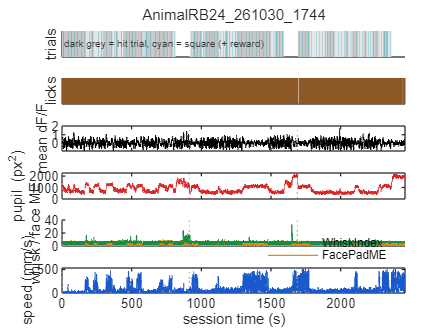

fh = newfig('Session overview', 18, 14);
tl = tiledlayout(fh, 6, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
title(tl, strrep(session, '_', '\_'), 'FontSize', 9, 'FontWeight', 'normal');
ax(1) = nexttile(tl);  hold on;
for k = 1:nTr
    patch([tr_t0(k) tr_t1(k) tr_t1(k) tr_t0(k)], [0 0 1 1], [0.9 0.9 0.9] - 0.12 * hit(k), 'EdgeColor', 'none');
    patch([on_t(k) st_end(k) st_end(k) on_t(k)], [0 0 1 1], col.sq, 'EdgeColor', 'none');
end
ylim([0 1]);  yticks([]);  ylabel('trials');
text(0.005, 0.5, 'dark grey = hit trial, cyan = square (+ reward)', 'Units', 'normalized', 'FontSize', 6, 'Color', [0.2 0.2 0.2]);
ax(2) = nexttile(tl);  hold on;
plot(repmat(lick_t(:)', 2, 1), repmat([0; 1], 1, numel(lick_t)), 'Color', col.lick, 'LineWidth', 0.3);
ylim([0 1]);  yticks([]);  ylabel('licks');
ax(3) = nexttile(tl);  plot(tCa, movmean(mean(dFF, 1), round(fs)), 'Color', col.dff);  ylabel('mean dF/F');
ax(4) = nexttile(tl);
if has_beh && isfield(data.Behav, 'PupilArea'); plot(tcam, data.Behav.PupilArea, 'Color', col.pupil); end
ylabel('pupil (px^2)');
ax(5) = nexttile(tl);  hold on;  h_face = gobjects(0);  h_whisk = gobjects(0);
if has_beh && isfield(data.Behav, 'FacePadME'); h_face = plot(tcam, data.Behav.FacePadME, 'Color', col.face); end
if has_beh && isfield(data.Behav, 'WhiskIndex'); h_whisk = plot(tcam, data.Behav.WhiskIndex, 'Color', col.whisk); end
ylabel('whisk / face ME');
if has_beh && all(isfield(data.Behav, {'WhiskIndex', 'FacePadME'})); legend([h_whisk, h_face], {'WhiskIndex', 'FacePadME'}, 'Location', 'northeast', 'FontSize', 7); end
ax(6) = nexttile(tl);  plot(tCa, loc_speed, 'Color', col.loc);  ylabel('speed (mm/s)');  xlabel('session time (s)');
if ~loc_ok; text(0.5, 0.5, 'locomotion unusable', 'Units', 'normalized', 'HorizontalAlignment', 'center', 'FontSize', 7); end
for a = 3:6; xline(ax(a), b_t0, 'Color', [0.6 0.6 0.6], 'LineStyle', ':', 'HandleVisibility', 'off'); end
linkaxes(ax, 'x');  xlim(ax(1), [tCa(1) tCa(end)]);
set(ax(1:5), 'XTickLabel', []);

if save_figs; savef(fh, '01_overview'); end

## 5. ROI signal quality (checks; the figures are in part C)

% Noise-referenced metrics (the pipeline dFF has median ~0 and std ~0.7 for pure noise, see header):
%   hf_noise   : per-frame noise = MAD of diff(dFF)/sqrt(2); events are slow compared with one frame, so they barely enter it
%   slow_ratio : var(smoothed dFF) / (hf_noise^2 / n_smooth) = variance of the smoothed trace relative to what white noise of
%                that per-frame level would leave after smoothing. White noise = 1, slow transients >> 1.
%   sig_neg    : noise sigma of the smoothed trace measured on the LOWER half only (calcium events only go up)
%   snr_slow   : (p99.9 - median)/sig_neg of the smoothed trace (Gaussian noise alone gives 3.1); reported, not used for the verdict
%   ev_pos / ev_neg : upward crossings of +3*sig_neg vs downward crossings of -3*sig_neg; events go up, so ev_pos >> ev_neg
Fc    = F - neuropil_factor * Fneu;
w_sm  = max(1, round(smooth_s * fs));
dsm   = movmean(dFF, w_sm, 2);
med_s = median(dsm, 2);
dev   = dsm - med_s;
neg   = dev < 0;
sig_neg  = max(sqrt(sum(dev.^2 .* neg, 2) ./ max(sum(neg, 2), 1)), eps('single'));
snr_slow = (prctile(dsm, 99.9, 2) - med_s) ./ sig_neg;
dd       = diff(dFF, 1, 2);
hf_noise = 1.4826 * median(abs(dd - median(dd, 2)), 2) / sqrt(2);
slow_ratio = var(dsm, 0, 2) ./ (hf_noise .^ 2 / w_sm);
up = dev >  3 * sig_neg;  dn = dev < -3 * sig_neg;
ev_pos = sum(diff([false(nROI, 1) up], 1, 2) == 1, 2);
ev_neg = sum(diff([false(nROI, 1) dn], 1, 2) == 1, 2);
frac_Fc_le0 = mean(Fc <= 0, 2);

% does the stored dFF follow from the stored F / Fneu / baseline with the settings above?
rows = 1:min(nROI, 30);
Fcr  = double(Fc(rows, :)) - double(F0(rows, :));
win_med = 2 * ceil(dff_window_s / median(dtc)) + 1;
den  = movmedian(Fcr, win_med, 2);
dFF_re = Fcr ./ den - 1;
re_err = median(abs(dFF_re - double(dFF(rows, :))), 2);
chk = addchk(chk, 'dFF: reproduces from F/Fneu/baseline', grade(max(re_err) < 1e-3, 1), sprintf('median |recomputed - stored| <= %.1e (neuropil %.2f, +-%g s). Larger = other settings were used', max(re_err), neuropil_factor, dff_window_s));
den_bad = false(nROI, 1);  den_bad(rows) = any(den <= 0, 2);
chk = addchk(chk, 'dFF: denominator > 0', grade(~any(den_bad), 1), sprintf('%d ROIs with movmedian(Fc - baseline) <= 0 (dF/F sign flips / explodes): %s', sum(den_bad), lst(find(den_bad)')));
chk = addchk(chk, 'F: neuropil over-subtraction', grade(~any(frac_Fc_le0 > 0.01), 1), sprintf('%d ROIs with Fc = F - %.1f*Fneu <= 0 in >1%% of frames: %s', sum(frac_Fc_le0 > 0.01), neuropil_factor, lst(find(frac_Fc_le0 > 0.01)')));

bad_F       = frac_Fc_le0 > 0.01 | den_bad;
noise_like  = slow_ratio < slow_ratio_thr | ev_pos < 2 * max(ev_neg, 1);
signal_like = ~bad_F & ~noise_like;
roiq = table((1:nROI)', cent(:, 1), cent(:, 2), arrayfun(@(c) c.npix, ca.Ca_cellstats(:)), median(F, 2), median(Fneu, 2), median(F0, 2), 100*frac_Fc_le0, ...
    std(dFF, 0, 2), skewness(double(dFF), 0, 2), hf_noise, slow_ratio, snr_slow, ev_pos, ev_neg, ev_pos / (nT/fs/60), signal_like, ...
    'VariableNames', {'roi','y','x','npix','F_med','Fneu_med','F0_med','pct_Fc_le0','std_dff','skew','hf_noise','slow_ratio','snr_slow','ev_pos','ev_neg','ev_per_min','signal_like'});
disp(roiq);

    roi     y      x     npix    F_med     Fneu_med    F0_med    pct_Fc_le0    std_dff     skew      hf_noise    slow_ratio    snr_slow    ev_pos    ev_neg    ev_per_min    signal_like
    ___    ___    ___    ____    ______    ________    ______    __________    _______    _______    ________    __________    ________    ______    ______    __________    ___________

     1     274    100    472     64.544     7.6825 

chk = addchk(chk, 'ROIs: signal-like', grade(sum(signal_like) >= max(3, 0.25 * nROI), 1), sprintf('%d/%d ROIs pass (slow_ratio >= %g, ev_pos >= 2*ev_neg, Fc > 0 in >99%% of frames). Noise-like: %s; neuropil-limited: %s', sum(signal_like), nROI, slow_ratio_thr, lst(find(noise_like & ~bad_F)'), lst(find(bad_F)')));
chk = addchk(chk, 'ROIs: pure-noise std level', grade(true, 1), sprintf('median std(dFF) %.2f (pure noise gives ~0.71 under this dF/F definition), median per-frame noise %.2f', median(std(dFF, 0, 2)), median(hf_noise)));
printchk(chk, n0);  n0 = size(chk, 1);

  [PASS] dFF: reproduces from F/Fneu/baseline median |recomputed - stored| <= 2.3e-08 (neuropil 0.50, +-15 s). Larger = other settings were used
  [PASS] dFF: denominator > 0                 0 ROIs with movmedian(Fc - baseline) <= 0 (dF/F sign flips / explodes): []
  [PASS] F: neuropil over-subtraction         0 ROIs with Fc = F - 0.5*Fneu <= 0 in >1% of frames: []
  [PASS] ROIs: signal-like                    8/11 ROIs pass (slow_ratio >= 4, ev_pos >= 2*ev_neg, Fc > 0 in >99% of frames). Noise-like: [4 6 7]; neuropil-limited: []
  [PASS] ROIs: pure-noise std level           median std(dFF) 0.75 (pure noise gives ~0.71 under this dF/F definition), median per-frame noise 0.61


## 6. Registration offset, FOV-wide events, drift and motion (checks; the figures are in part C)

% 6a. suite2p crops max_proj to the valid registered area, while ROI pixel coordinates (ypix/xpix, centroids) are in full-frame
% coordinates. Overlaying them directly shifts every ROI. The shift is found by maximising the mean Img_max intensity under the ROI pixels.
off = [0 0];  pl_rois = [];  yp = {};  xp = {};
if has_img
    pl_i = min(plane_show, numel(planes));
    im   = double(data.Img_max{pl_i, 1});  [Ly, Lx] = size(im);
    pl_rois = find(cent(:, 3) == planes(pl_i))';
    cs   = ca.Ca_cellstats;
    yp = cell(numel(pl_rois), 1);  xp = yp;
    for j = 1:numel(pl_rois); yp{j} = double(cs(pl_rois(j)).ypix(:)); xp{j} = double(cs(pl_rois(j)).xpix(:)); end
    allY = vertcat(yp{:});  allX = vertcat(xp{:});
    pick = round(linspace(1, numel(allY), min(numel(allY), 20000)));
    sy = allY(pick);  sx = allX(pick);
    shifts = -25:25;
    reg_score = nan(numel(shifts));
    for a = 1:numel(shifts)
        for b = 1:numel(shifts)
            yy = sy + 1 + shifts(a);  xx = sx + 1 + shifts(b);          % +1: suite2p pixels are 0-based
            okp = yy >= 1 & yy <= Ly & xx >= 1 & xx <= Lx;
            if mean(okp) > 0.9; reg_score(a, b) = mean(im(sub2ind([Ly Lx], yy(okp), xx(okp)))); end
        end
    end
    [mx, ix] = max(reg_score(:));  [ia, ib] = ind2sub(size(reg_score), ix);
    auto_off = [shifts(ia) shifts(ib)];
    score0   = reg_score(shifts == 0, shifts == 0);
    if ischar(roi_img_offset); off = auto_off; else; off = roi_img_offset; end
    full_sz  = [NaN NaN];
    if has_si; full_sz = double([data.SI_Info.hRoiManager.linesPerFrame data.SI_Info.hRoiManager.pixelsPerLine]); end
    chk = addchk(chk, 'ROI map: Img_max registration', grade(all(auto_off == 0) || mx / score0 > 1.05, 1), ...
        sprintf('Img_max %dx%d (frame %dx%d); ROI pixels land best at shift dy=%d dx=%d, mean intensity under ROIs %.1f vs %.1f unshifted (x%.2f); using [%d %d]', Ly, Lx, full_sz(1), full_sz(2), auto_off(1), auto_off(2), mx, score0, mx / score0, off(1), off(2)));
end

% 6b. FOV-wide events (many ROIs up at the same time) are typically motion, neuropil or arousal, not single-axon activity.
sl = find(signal_like)';  if numel(sl) < 3; sl = 1:nROI; end
co = mean(up(sl, :), 1);                                    % fraction of (signal-like) ROIs above +3 sigma at each frame
null_co = zeros(1, n_perm);
for p = 1:n_perm
    sh = randi([round(30*fs), nT - round(30*fs)], numel(sl), 1);
    idx = mod((0:nT-1) + sh, nT) + 1;                       % independent circular shift per ROI
    null_co(p) = max(mean(up(sub2ind(size(up), repmat(sl(:), 1, nT), idx)), 1));
end
co_thr = max(0.4, 1.2 * max(null_co));
g_on   = find(diff([0 co >= co_thr]) == 1);
if ~isempty(g_on); g_on = g_on([true, diff(tCa(g_on)) > 1]); end    % merge events closer than 1 s
g_t    = tCa(g_on);
g_trl  = arrayfun(@(t) find(t >= tr_t0 & t <= tr_t1, 1), g_t, 'UniformOutput', false);
g_trl(cellfun(@isempty, g_trl)) = {0};
chk = addchk(chk, 'population: FOV-wide events', grade(numel(g_t) <= 3, 1), sprintf('%d events with >= %.0f%% of %d ROIs up together (chance max %.0f%%), at s: %s (trials %s, 0 = break)', numel(g_t), 100*co_thr, numel(sl), 100*max(null_co), lst(round(g_t(1:min(end, 12)))), lst(cell2mat(g_trl(1:min(end, 12))))));
% FOV-wide events locked to the square? count those 0-3 s after an onset against the number expected for random times inside trials
task_time = sum(tr_t1 - tr_t0);
n_on_ev   = sum(arrayfun(@(t) any(t >= on_t & t <= on_t + resp_win(2)), g_t));
n_exp_ev  = numel(g_t) * nTr * diff(resp_win) / task_time;
chk = addchk(chk, 'population: events locked to the square', grade(~(n_on_ev >= 3 && n_on_ev > n_exp_ev + 3 * sqrt(max(n_exp_ev, 1))), 1), sprintf('%d of %d FOV-wide events fall %g-%g s after a square onset (%.1f expected for random times in the trials): a square-locked FOV-wide event points to a light leak, motion or global arousal, not to single axons', n_on_ev, numel(g_t), resp_win(1), resp_win(2), n_exp_ev));
ev_in_glob = nan(nROI, 1);
for r = 1:nROI
    on_r = tCa(diff([0 up(r, :)]) == 1);
    if ~isempty(on_r) && ~isempty(g_t); ev_in_glob(r) = mean(min(abs(on_r(:) - g_t(:)'), [], 2) <= 1); elseif ~isempty(on_r); ev_in_glob(r) = 0; end
end
chk = addchk(chk, 'population: events during FOV-wide events', grade(~(median(ev_in_glob(signal_like), 'omitnan') > 0.3), 1), sprintf('median %.0f%% of signal-like ROI events fall within 1 s of a FOV-wide event', 100*median(ev_in_glob(signal_like), 'omitnan')));

% correlation between ROIs (smoothed dFF): ROIs on the same axon share their events (r close to 1) and are NOT independent samples
ids = sl;  if numel(ids) < 3; ids = 1:min(nROI, 300); end
[~, so] = sort(slow_ratio(ids), 'descend');  ids = ids(so);
Cm = corrcoef(double(dsm(ids, :))');
px_um = NaN;  if has_si; px_um = abs(diff(data.SI_Info.hRoiManager.imagingFovUm([1 2]))) / data.SI_Info.hRoiManager.pixelsPerLine; end
[pa, pb] = find(triu(Cm > 0.8, 1));
pair_d = hypot(cent(ids(pa), 1) - cent(ids(pb), 1), cent(ids(pa), 2) - cent(ids(pb), 2));
chk = addchk(chk, 'ROIs: strongly correlated pairs', grade(isempty(pa), 1), sprintf('%d of %d pairs among the %d signal-like ROIs have r > 0.8 (same axon / shared signal, not independent); median centroid distance %.0f px = %.0f um', numel(pa), numel(ids)*(numel(ids)-1)/2, numel(ids), median(pair_d), median(pair_d) * px_um));
if ~isempty(pa)
    pr = Cm(sub2ind(size(Cm), pa, pb));  [~, po] = sort(pr, 'descend');  po = po(1:min(10, numel(po)));
    disp(table(ids(pa(po))', ids(pb(po))', pr(po), pair_d(po), 'VariableNames', {'roiA','roiB','r','dist_px'}));
end

    roiA    roiB       r       dist_px
    ____    ____    _______    _______

      2      9      0.90165     60.44 
      2      1      0.89505    79.076 
      2      8      0.85566    47.381 
      1      8      0.83228    49.659 
     11      5      0.83138    231.62 
     10      3      0.82746    42.202 
      9      8      0.81866    30.232 
      1      9      0.80189    20.396 




% bleaching / drift of the raw ROI fluorescence (median per minute, relative to the first minute)
bn = round(60 * fs);  nb = floor(nT / bn);
Fb = reshape(median(reshape(double(Fc(:, 1:nb*bn)), nROI, bn, nb), 2), nROI, nb);
Fb_rel = Fb ./ Fb(:, 1);  Fb_rel(Fb(:, 1) <= 0, :) = NaN;
drift_pct = 100 * (median(Fb_rel(:, end), 'omitnan') - 1);
chk = addchk(chk, 'F: drift over session', grade(abs(drift_pct) < 30, 1), sprintf('median ROI Fc changes %.0f%% from first to last minute (bleaching / z-drift)', drift_pct));

% 6c. motion (optional: needs suite2p Fall.mat, not stored in the aggregated file)
% Rigid shift = ops.xoff/yoff, non-rigid deformation = spread of the block shifts ops.xoff1/yoff1. ROIs whose dFF follows motion are not axon signal.
motion_r = nan(nROI, 2);  mot_flag = false(nROI, 1);  have_motion = false;  rigid = nan(1, nT);  nonr = rigid;  thr99 = nan(nROI, 2);  mot_names = {'rigid', 'non-rigid'};
fall_file = fullfile(s2p_dir, 'Fall.mat');
if isfile(fall_file)
    o   = load(fall_file, 'ops');  ops = o.ops;
    xo  = double(ops.xoff(:))';  yo = double(ops.yoff(:))';
    len_ok = numel(xo) == nT;
    chk = addchk(chk, 'motion: ops length', grade(len_ok, 1), sprintf('%d motion samples vs %d frames', numel(xo), nT));
    if len_ok
        have_motion = true;
        rigid = hypot(xo - median(xo), yo - median(yo));
        nonr  = hypot(std(double(ops.xoff1), 0, 2), std(double(ops.yoff1), 0, 2))';
        bad_f = false(1, nT);  if isfield(ops, 'badframes'); bad_f = logical(ops.badframes(:))'; end
        mot_lim_px = 1 / px_um;  if ~isfinite(mot_lim_px); mot_lim_px = 6; end             % 1 um, about the width of an axon
        chk = addchk(chk, 'motion: rigid shift', grade(prctile(rigid, 99) < mot_lim_px, 1), sprintf('p99 %.1f px = %.2f um, max %.1f px (x %d..%d, y %d..%d px); WARN above %.1f px (1 um); %.2f%% frames flagged bad by suite2p', prctile(rigid, 99), prctile(rigid, 99) * px_um, max(rigid), min(xo), max(xo), min(yo), max(yo), mot_lim_px, 100*mean(bad_f)));
        mots = {rigid, nonr};
        null_r = zeros(nROI, n_perm, 2);
        for m = 1:2
            mv = movmean(mots{m}, w_sm);
            mz = (mv - mean(mv)) / std(mv);
            dz = (double(dsm) - mean(double(dsm), 2)) ./ std(double(dsm), 0, 2);
            motion_r(:, m) = dz * mz' / (nT - 1);
            for p = 1:n_perm
                null_r(:, p, m) = dz * circshift(mz, randi([round(30*fs), nT - round(30*fs)]))' / (nT - 1);
            end
        end
        thr99 = squeeze(prctile(abs(null_r), 99, 2));                              % [nROI x 2]
        mot_flag = any(abs(motion_r) > max(thr99, mot_r_thr), 2);
        chk = addchk(chk, 'motion: ROIs coupled to motion', grade(~any(mot_flag & signal_like), 1), sprintf('%d ROIs follow rigid / non-rigid motion beyond shuffle (|r| > shuffle p99 and > %.2f); %d of them signal-like: %s. Median |r| rigid %.2f, non-rigid %.2f', sum(mot_flag), mot_r_thr, sum(mot_flag & signal_like), lst(find(mot_flag & signal_like)'), median(abs(motion_r(:, 1))), median(abs(motion_r(:, 2)))));
    end
else
    chk = addchk(chk, 'motion: suite2p ops', grade(false, 1), sprintf('not checked: %s not found', fall_file));
end
printchk(chk, n0);  n0 = size(chk, 1);

  [PASS] ROI map: Img_max registration        Img_max 502x504 (frame 512x512); ROI pixels land best at shift dy=-4 dx=-5, mean intensity under ROIs 38.5 vs 32.8 unshifted (x1.17); using [-4 -5]
  [WARN] population: FOV-wide events          7 events with >= 60% of 8 ROIs up together (chance max 50%), at s: [317 873 895 1994 1997 2162 2205] (trials [12 0 0 73 74 81 83], 0 = break)
  [PASS] population: events locked to the square 1 of 7 FOV-wide events fall 0-3 s after a square onset (0.9 expected for random times in the trials): a square-locked FOV-wide event points to a light leak, motion or global arousal, not to single axons
  [PASS] population: events during FOV-wide events median 12% of signal-like ROI events fall within 1 s of a FOV-wide event
  [WARN] ROIs: strongly correlated pairs      8 of 28 pairs among the 8 signal-like ROIs have r > 0.8 (same axon / shared signal, not independent); median centroid distance 49 px = 13 um
  [PASS] F: drift over session                median RO

## 7. ROI selection

% Everything in part B (figures, tables) uses sel_roi. Part A stays on all ROIs so the checks are unchanged.
good_roi = find(signal_like & ~mot_flag)';
if ischar(roi_sel) || isstring(roi_sel)
    switch lower(char(roi_sel))
        case 'all';  sel_roi = 1:nROI;
        case 'signal'; sel_roi = find(signal_like)';
        case 'good'
            sel_roi = good_roi;
            if isempty(sel_roi); sel_roi = find(signal_like)'; chk = addchk(chk, 'ROI selection: fallback', grade(false, 1), 'no signal-like ROI is free of motion coupling: using the signal-like ROIs'); end
            if isempty(sel_roi); sel_roi = 1:nROI; chk = addchk(chk, 'ROI selection: fallback', grade(false, 1), 'no signal-like ROI at all: using all ROIs'); end
        otherwise;   error('roi_sel must be ''all'', ''signal'', ''good'' or a list of ROI numbers');
    end
else
    sel_roi = unique(double(roi_sel(:)'));
    assert(all(sel_roi >= 1 & sel_roi <= nROI & sel_roi == round(sel_roi)), 'roi_sel: ROI numbers must be integers between 1 and %d', nROI);
end
assert(~isempty(sel_roi), 'roi_sel selects no ROIs');
nSel = numel(sel_roi);
flagged = sel_roi(noise_like(sel_roi) | bad_F(sel_roi) | mot_flag(sel_roi));
chk = addchk(chk, 'ROI selection', grade(isempty(flagged) || ischar(roi_sel) || isstring(roi_sel), 1), ...
    sprintf('%d/%d ROIs selected (roi_sel = %s): %s. Flagged by the checks (noise-like / Fc<=0 / motion-coupled): %s', nSel, nROI, strtrim(evalc('disp(roi_sel)')), lst(sel_roi), lst(flagged)));
printchk(chk, n0);  n0 = size(chk, 1);

  [PASS] ROI selection                        8/11 ROIs selected (roi_sel = signal): [1 2 3 5 8 9 10 11]. Flagged by the checks (noise-like / Fc<=0 / motion-coupled): [1 2 5 8 9 11]


## 8. ROI groups, trial table and lick behaviour

% One axon branching over the field gives several ROIs with the same signal (r > grp_r_thr on the smoothed dF/F): they are not independent samples.
% sel_roi is clustered and every trial statistic below uses the group means (group 1 = the largest group).
rng(2);
dFFd = double(dFF);
if nSel >= 2; gid = cluster(linkage(pdist(double(dsm(sel_roi, :)), 'correlation'), 'average'), 'cutoff', 1 - grp_r_thr, 'criterion', 'distance'); else; gid = ones(nSel, 1); end
gid = gid(:)';
gsz = accumarray(gid(:), 1)';  gmn = accumarray(gid(:), sel_roi(:), [], @min)';
[~, gord] = sort(-1000 * gsz + gmn);
[~, gid] = ismember(gid, gord);
ng = max(gid);
grp_rois = arrayfun(@(g) sel_roi(gid == g), 1:ng, 'UniformOutput', false);
grp_lab  = cellfun(@(r) ['ROI ' regexprep(num2str(r), '\s+', ',')], grp_rois, 'UniformOutput', false);
grp_mot  = cellfun(@(r) any(mot_flag(r)), grp_rois);
grp_mean = cell2mat(cellfun(@(r) mean(dFFd(r, :), 1), grp_rois(:), 'UniformOutput', false));     % [ng x nT]
gcol     = lines(ng);  gcol(1, :) = [0 0 0];
% control: the noise-like ROIs outside the selection. They carry no axonal signal, so whatever they show at the square or around licking is common-mode
% (motion, neuropil, z-shift) and is the reference for the groups. It is added as the last row of every statistic below (the figures show the groups only).
ctl_roi = find(noise_like & ~bad_F & ~ismember((1:nROI)', sel_roi))';
ngc = ng + double(~isempty(ctl_roi));
grp_all = grp_mean;  glab_all = grp_lab;
if ~isempty(ctl_roi)
    grp_all = [grp_mean; mean(dFFd(ctl_roi, :), 1)];
    glab_all = [grp_lab, {['control: noise-like ROI ' regexprep(num2str(ctl_roi), '\s+', ',')]}];
end
roi_lab  = string(sel_roi);  roi_skip = max(1, ceil(nSel / 40));
fprintf('\nROI groups (r > %g on the smoothed dF/F):\n', grp_r_thr);


ROI groups (r > 0.8 on the smoothed dF/F):


for g = 1:ng; fprintf('  group %d: %s%s\n', g, grp_lab{g}, iff(grp_mot(g), '  (contains motion-coupled ROIs)', '')); end

  group 1: ROI 1,2,8,9  (contains motion-coupled ROIs)
  group 2: ROI 3,10
  group 3: ROI 5,11  (contains motion-coupled ROIs)



% findings table: {analysis, statistic, value, ci or p, n}
ex = cell(0, 5);
exadd = @(c, a, b, v, ci, n) [c; {a, b, v, ci, n}];
ci_str = @(x) sprintf('[%.2f, %.2f]', x(1), x(2));
boot_ci = @(x, f) prctile(arrayfun(@(b) f(x(randi(numel(x), numel(x), 1))), 1:n_boot), [2.5 97.5]);

% behaviour in session SD on the imaging grid (rows of beh_names), plus the rigid shift
nBeh = numel(beh_names);
BZ = nan(nBeh, nT);
for si = 1:nBeh; x = beh_ca.(beh_names{si}); BZ(si, :) = (x - mean(x, 'omitnan')) / std(x, 'omitnan'); end
rig_z = zeros(1, nT);  if have_motion; rig_z = (rigid - mean(rigid)) / std(rigid); end
XB = BZ;  xb_names = beh_names;
if have_motion; XB = [XB; rig_z];  xb_names = [xb_names, {'RigidShift'}]; end
nXB = numel(xb_names);
xb_col = cellfun(@(n) beh_cmap.(n), xb_names, 'UniformOutput', false);
xb_lab = cellfun(@(n) beh_lab.(n), xb_names, 'UniformOutput', false);
xi_ = @(nm) find(strcmp(xb_names, nm), 1);

% trial table
trl = table((1:nTr)', sub_of, wait_s, n_to, on_t, hit, n_win, lat1, cons_lat, cons_n, n_pre, n_post, ...
    'VariableNames', {'trial', 'subsession', 'wait_s', 'timeouts', 'onset_s', 'hit', 'licks_0p1_2s', 'first_lick_lat_s', 'bout_lat_s', 'bout_licks', 'licks_pre5s', 'licks_post5s'});
sub_tbl = table((1:nB)', accumarray(sub_of, 1), 100 * accumarray(sub_of, hit) ./ accumarray(sub_of, 1), accumarray(sub_of, lat1, [], @(x) median(x, 'omitnan')), accumarray(sub_of, n_to), accumarray(sub_of, n_pre) / S.trials, ...
    'VariableNames', {'subsession', 'trials', 'hit_pct', 'median_first_lick_s', 'timeouts', 'licks_5s_before'});
disp(sub_tbl);

    subsession    trials    hit_pct    median_first_lick_s    timeouts    licks_5s_before
    __________    ______    _______    ___________________    ________    _______________

        1           30      76.667           1.0466              16              5.8     
        2           30      73.333           1.2474               4           6.1333     
        3           30          50           1.9772               4              4.2     



rate_pre = n_pre / 5;
fprintf('Hit trials: %d/%d. First lick after the reward within %g s in %d trials, median latency %.2f s (hit trials %.2f s, other %.2f s).\n', sum(hit), nTr, cons_max_s, sum(isfinite(lat1)), median(lat1, 'omitnan'), median(lat1(hit), 'omitnan'), median(lat1(~hit), 'omitnan'));

Hit trials: 60/90. First lick after the reward within 6 s in 90 trials, median latency 1.35 s (hit trials 0.62 s, other 3.02 s).


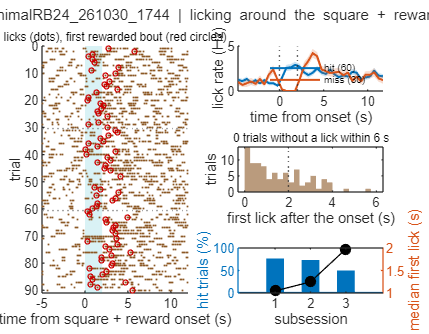

ex = exadd(ex, '8 licking', 'hit rate (lick 0.1-2 s after the square), %', P_mine, sprintf('log P = %.1f', S.P), nTr);
ex = exadd(ex, '8 licking', 'trials with a lick within cons_max_s of the reward, %', 100 * mean(isfinite(lat1)), '', nTr);
ex = exadd(ex, '8 licking', 'median first-lick latency (s)', median(lat1, 'omitnan'), ci_str(boot_ci(lat1(isfinite(lat1)), @median)), sum(isfinite(lat1)));
ex = exadd(ex, '8 licking', 'licks per s in the 5 s before the square', mean(rate_pre), ci_str(boot_ci(rate_pre, @mean)), nTr);

% figure 02: lick behaviour
ed = -ev_pre_s:0.5:ev_post_s;  ctr = ed(1:end-1) + 0.25;
LC = zeros(nTr, numel(ctr));
for t = 1:nTr; LC(t, :) = histcounts(lick_t - on_t(t), ed) / 0.5; end
col_hit = [0 0.45 0.74];  col_mis = [0.85 0.33 0.1];
fh = newfig('Lick behaviour', 18, 14);
tl = tiledlayout(fh, 3, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
title(tl, [strrep(session, '_', '\_') ' | licking around the square + reward'], 'FontSize', 9, 'FontWeight', 'normal');
a1 = nexttile(tl, 1, [3 1]);  hold(a1, 'on');
patch(a1, [0 lw(2) lw(2) 0], [0 0 nTr + 1 nTr + 1], col.sq, 'FaceAlpha', 0.15, 'EdgeColor', 'none');
rx = cell(nTr, 1);  ry = rx;
for t = 1:nTr; r_ = lick_t - on_t(t);  r_ = r_(r_ >= -ev_pre_s & r_ <= ev_post_s);  rx{t} = r_;  ry{t} = t * ones(size(r_)); end
plot(a1, vertcat(rx{:}), vertcat(ry{:}), '.', 'Color', col.lick, 'MarkerSize', 3);
plot(a1, cons_lat(isfinite(cons_lat)), find(isfinite(cons_lat)), 'o', 'Color', [0.8 0 0], 'MarkerSize', 3);
yline(a1, (1:nB - 1) * S.trials + 0.5, ':', 'Color', [0.5 0.5 0.5]);
set(a1, 'YDir', 'reverse');  xlim(a1, [-ev_pre_s ev_post_s]);  ylim(a1, [0 nTr + 1]);  xlabel(a1, 'time from square + reward onset (s)');  ylabel(a1, 'trial');
title(a1, 'licks (dots), first rewarded bout (red circles)', 'FontSize', 7, 'FontWeight', 'normal');
a2 = nexttile(tl, 2);  hold(a2, 'on');
h2 = [sem_trace(a2, ctr, LC(hit, :)', col_hit, true), sem_trace(a2, ctr, LC(~hit, :)', col_mis, true)];
xline(a2, [0 lw(2)], ':');  ylabel(a2, 'lick rate (Hz)');  xlabel(a2, 'time from onset (s)');  legend(a2, h2, {sprintf('hit (%d)', sum(hit)), sprintf('miss (%d)', sum(~hit))}, 'FontSize', 6);
a3 = nexttile(tl, 4);  histogram(a3, lat1, 0:0.25:cons_max_s, 'FaceColor', col.lick, 'EdgeColor', 'none');  xline(a3, lw(2), ':');
xlabel(a3, 'first lick after the onset (s)');  ylabel(a3, 'trials');  title(a3, sprintf('%d trials without a lick within %g s', sum(~isfinite(lat1)), cons_max_s), 'FontSize', 7, 'FontWeight', 'normal');
a4 = nexttile(tl, 6);  yyaxis(a4, 'left');  bar(a4, 1:nB, sub_tbl.hit_pct, 0.5, 'FaceColor', col_hit, 'EdgeColor', 'none');  ylabel(a4, 'hit trials (%)');  ylim(a4, [0 100]);
yyaxis(a4, 'right');  plot(a4, 1:nB, sub_tbl.median_first_lick_s, 'ko-', 'MarkerFaceColor', 'k');  ylabel(a4, 'median first lick (s)');  xticks(a4, 1:nB);  xlabel(a4, 'subsession');

if save_figs; savef(fh, '02_lick_behaviour'); end

## 9. Square + reward onset response

% Both start at the same frame, so this is the response to the compound event. Alignment: first square frame (2P clock); baseline base_win, response resp_win.
% Null: the same statistic at pseudo-onsets drawn at random inside the wait periods (same state of the animal: waiting, licking at ~1 Hz), nTr of them per draw.
% A pseudo-baseline starts at least ps_min_s after the trial start, like the real baselines (wait >= 8 s, baseline from 3 s before the square), because dF/F
% still decays for several s after the previous reward and pseudo-onsets right after the trial start would show a negative 'response'.
n_com = round((ev_pre_s + ev_post_s) * fs) + 1;  tev = linspace(-ev_pre_s, ev_post_s, n_com);
bi_ = tev >= base_win(1) & tev < base_win(2);  ri_ = tev >= resp_win(1) & tev <= resp_win(2);
Cg = align_trials_to_onsets(on_t, grp_all, tCa, ev_pre_s, ev_post_s, n_com);        % [ng x time x trials]
Cg_base = mean(Cg(:, bi_, :), 2, 'omitnan');  Cg = Cg - Cg_base;
Cr = align_trials_to_onsets(on_t, dFFd(sel_roi, :), tCa, ev_pre_s, ev_post_s, n_com);
Cr = Cr - mean(Cr(:, bi_, :), 2, 'omitnan');
Bal = align_trials_to_onsets(on_t, XB, tCa, ev_pre_s, ev_post_s, n_com);             % [behaviour x time x trials], session SD
Braw = Bal;  Braw_base = mean(Bal(:, bi_, :), 2, 'omitnan');  Bal = Bal - Braw_base;
amp = reshape(mean(Cg(:, ri_, :), 2, 'omitnan'), ngc, nTr);                           % mean dF/F change in resp_win, per group and trial

% pseudo-onsets
n_ps = 6;  ps_t = [];  ps_min_s = 5;
for t = 1:nTr
    lo = tr_t0(t) + ps_min_s - base_win(1);  hi = on_t(t) - resp_win(2) - 0.5;
    if hi > lo; ps_t = [ps_t; lo + (hi - lo) * rand(n_ps, 1)]; end %#ok<AGROW>
end
n_cps = round((-base_win(1) + resp_win(2)) * fs) + 1;  t_ps = linspace(base_win(1), resp_win(2), n_cps);
Cps = align_trials_to_onsets(ps_t, grp_all, tCa, -base_win(1), resp_win(2), n_cps);
Cps = Cps - mean(Cps(:, t_ps >= base_win(1) & t_ps < base_win(2), :), 2, 'omitnan');
amp_ps = reshape(mean(Cps(:, t_ps >= resp_win(1) & t_ps <= resp_win(2), :), 2, 'omitnan'), ngc, []);
n_ps_tot = size(amp_ps, 2);
chk = addchk(chk, 'onset response: pseudo-onsets', grade(n_ps_tot >= 100, 1), sprintf('%d pseudo-onsets from %d trials with a wait long enough (baseline >= %g s after the trial start); the null for the %d real onsets is built from them', n_ps_tot, round(n_ps_tot / n_ps), ps_min_s, nTr));
null_amp = zeros(ngc, n_perm);  null_tr = zeros(ngc, n_cps, n_perm);
for b = 1:n_perm
    ix = randi(n_ps_tot, nTr, 1);
    null_amp(:, b) = mean(amp_ps(:, ix), 2);  null_tr(:, :, b) = mean(Cps(:, :, ix), 3);
end
null_band = prctile(null_tr, [2.5 97.5], 3);                                         % [ng x time x 2]
obs_amp = mean(amp, 2);
p_on = (1 + sum(abs(null_amp) >= abs(obs_amp), 2)) / (n_perm + 1);
fprintf('\n9 square + reward onset response (mean dF/F change %g-%g s after onset, %d trials; null = %d pseudo-onsets in the wait periods)\n', resp_win(1), resp_win(2), nTr, n_ps_tot);


9 square + reward onset response (mean dF/F change 0-3 s after onset, 90 trials; null = 252 pseudo-onsets in the wait periods)


p_hm = nan(ngc, 1);  d_hm = nan(ngc, 1);  ci_hm = nan(ngc, 2);
for g = 1:ngc
    a = amp(g, :)';
    ci = boot_ci(a, @mean);
    ex = exadd(ex, ['9 onset response, ' glab_all{g}], sprintf('mean dF/F change %g-%g s (pseudo-onset null mean %+.3f, sd %.3f)', resp_win(1), resp_win(2), mean(null_amp(g, :)), std(null_amp(g, :))), obs_amp(g), sprintf('%s, perm p=%.3f, signrank p=%.3g', ci_str(ci), p_on(g), signrank(a)), nTr);
    if sum(hit) >= 3 && sum(~hit) >= 3
        d_hm(g) = mean(a(hit)) - mean(a(~hit));
        ah = a(hit);  am = a(~hit);
        bs = arrayfun(@(b) mean(ah(randi(numel(ah), numel(ah), 1))) - mean(am(randi(numel(am), numel(am), 1))), 1:n_boot);
        ci_hm(g, :) = prctile(bs, [2.5 97.5]);
        pl_ = zeros(1, n_perm);
        for b = 1:n_perm; h_ = hit(randperm(nTr)); pl_(b) = mean(a(h_)) - mean(a(~h_)); end
        p_hm(g) = (1 + sum(abs(pl_) >= abs(d_hm(g)))) / (n_perm + 1);
        ex = exadd(ex, ['9 hit vs miss, ' glab_all{g}], 'mean dF/F change, hit minus miss', d_hm(g), sprintf('%s, label-permutation p=%.3f', ci_str(ci_hm(g, :)), p_hm(g)), sum(hit));
    end
    fprintf('  %s: %+.3f dF/F %s (null %+.3f +- %.3f, p=%.3f); hit - miss %+.3f %s (p=%.3f)\n', glab_all{g}, obs_amp(g), ci_str(ci), mean(null_amp(g, :)), std(null_amp(g, :)), p_on(g), d_hm(g), ci_str(ci_hm(g, :)), p_hm(g));
end

  ROI 1,2,8,9: +0.163 dF/F [0.06, 0.27] (null -0.068 +- 0.036, p=0.015); hit - miss +0.497 [0.32, 0.66] (p=0.005)
  ROI 3,10: +0.027 dF/F [-0.08, 0.13] (null -0.128 +- 0.052, p=0.980); hit - miss +0.218 [-0.01, 0.43] (p=0.055)
  ROI 5,11: +0.056 dF/F [-0.02, 0.15] (null -0.061 +- 0.028, p=0.562); hit - miss +0.184 [0.01, 0.35] (p=0.030)
  control: noise-like ROI 4,6,7: +0.005 dF/F [-0.02, 0.03] (null -0.009 +- 0.009, p=0.751); hit - miss +0.085 [0.05, 0.12] (p=0.005)


ev_beh = reshape(mean(Bal(:, ri_, :), 2, 'omitnan'), nXB, nTr);
fprintf('  behaviour change in the same window (session SD): %s\n', strjoin(arrayfun(@(i) sprintf('%s %+.2f', xb_names{i}, mean(ev_beh(i, :), 'omitnan')), 1:nXB, 'UniformOutput', false), ', '));

  behaviour change in the same window (session SD): PupilArea +0.00, WhiskIndex +0.15, FacePadME +0.05, EyeLidOpening +0.06, LocSpeed +0.03, LickRate +0.32, RigidShift +0.18


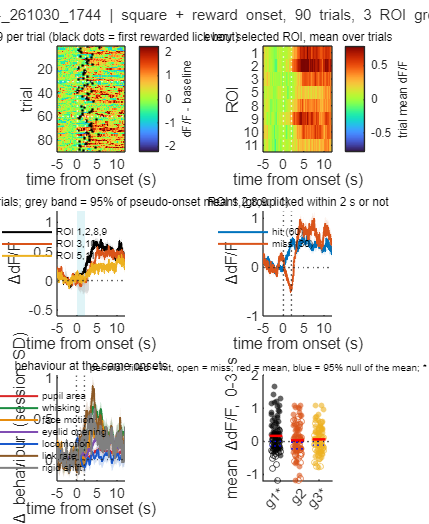

for i = 1:nXB; ex = exadd(ex, '9 behaviour at the onset', [xb_lab{i} ', change in resp_win (session SD)'], mean(ev_beh(i, :), 'omitnan'), ci_str(boot_ci(ev_beh(i, isfinite(ev_beh(i, :)))', @mean)), nTr); end

% figure 03
cmap_hm = turbo;
fh = newfig('Onset response', 18, 22);
tl = tiledlayout(fh, 3, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
title(tl, sprintf('%s | square + reward onset, %d trials, %d ROI group(s)', strrep(session, '_', '\_'), nTr, ng), 'FontSize', 9, 'FontWeight', 'normal');
a1 = nexttile(tl, 1);
Mh = squeeze(Cg(1, :, :))';  imagesc(a1, tev, 1:nTr, Mh);  cm = max(0.5, prctile(abs(Mh(:)), 99));  clim(a1, [-cm cm]);  colormap(a1, cmap_hm);  hold(a1, 'on');
plot(a1, cons_lat(isfinite(cons_lat)), find(isfinite(cons_lat)), 'k.', 'MarkerSize', 4);
xline(a1, [0 lw(2)], 'w:');  yline(a1, (1:nB - 1) * S.trials + 0.5, 'w:');  xlabel(a1, 'time from onset (s)');  ylabel(a1, 'trial');  cb = colorbar(a1);  cb.Label.String = 'dF/F - baseline';  cb.FontSize = 7;
title(a1, [grp_lab{1} ' per trial (black dots = first rewarded lick bout)'], 'FontSize', 7, 'FontWeight', 'normal');
a2 = nexttile(tl, 2);
Mr = squeeze(mean(Cr, 3));  if nSel == 1; Mr = Mr(:)'; end
imagesc(a2, tev, 1:nSel, Mr);  cm = max(0.3, prctile(abs(Mr(:)), 99));  clim(a2, [-cm cm]);  colormap(a2, cmap_hm);  xline(a2, [0 lw(2)], 'w:');
yticks(a2, 1:roi_skip:nSel);  yticklabels(a2, roi_lab(1:roi_skip:nSel));  xlabel(a2, 'time from onset (s)');  ylabel(a2, 'ROI');  cb = colorbar(a2);  cb.Label.String = 'trial mean dF/F';  cb.FontSize = 7;
title(a2, 'every selected ROI, mean over trials', 'FontSize', 7, 'FontWeight', 'normal');
a3 = nexttile(tl, 3);  hold(a3, 'on');
patch(a3, [0 lw(2) lw(2) 0], [-1 -1 1 1] * 1e3, col.sq, 'FaceAlpha', 0.12, 'EdgeColor', 'none');
fill(a3, [t_ps fliplr(t_ps)], [squeeze(null_band(1, :, 1)) fliplr(squeeze(null_band(1, :, 2)))], [0.7 0.7 0.7], 'FaceAlpha', 0.5, 'EdgeColor', 'none');
hg = gobjects(1, ng);  for g = 1:ng; hg(g) = sem_trace(a3, tev, squeeze(Cg(g, :, :)), gcol(g, :), true); end
yline(a3, 0, ':');  xlabel(a3, 'time from onset (s)');  ylabel(a3, '\DeltadF/F');  xlim(a3, tev([1 end]));
yl_ = [min(mean(Cg(1, :, :), 3), [], 'omitnan'), max(mean(Cg(1, :, :), 3), [], 'omitnan')];  ylim(a3, yl_ + [-1 1] * 0.6 * max(0.1, diff(yl_)));
legend(a3, hg, grp_lab, 'FontSize', 6, 'Location', 'northeast');
title(a3, 'mean +- SEM over trials; grey band = 95% of pseudo-onset means (group 1)', 'FontSize', 7, 'FontWeight', 'normal');
a4 = nexttile(tl, 4);  hold(a4, 'on');
h4 = [sem_trace(a4, tev, squeeze(Cg(1, :, hit)), col_hit, true), sem_trace(a4, tev, squeeze(Cg(1, :, ~hit)), col_mis, true)];
xline(a4, [0 lw(2)], ':');  yline(a4, 0, ':');  xlabel(a4, 'time from onset (s)');  ylabel(a4, '\DeltadF/F');  xlim(a4, tev([1 end]));
legend(a4, h4, {sprintf('hit (%d)', sum(hit)), sprintf('miss (%d)', sum(~hit))}, 'FontSize', 6);
title(a4, [grp_lab{1} ': licked within ' num2str(lw(2)) ' s or not'], 'FontSize', 7, 'FontWeight', 'normal');
a5 = nexttile(tl, 5);  hold(a5, 'on');  hb = gobjects(1, nXB);
for i = 1:nXB; hb(i) = sem_trace(a5, tev, squeeze(Bal(i, :, :)), xb_col{i}, true); end
xline(a5, [0 lw(2)], ':');  yline(a5, 0, ':');  xlabel(a5, 'time from onset (s)');  ylabel(a5, '\Delta behaviour (session SD)');  xlim(a5, tev([1 end]));  legend(a5, hb, xb_lab, 'FontSize', 6, 'Location', 'northeast');
title(a5, 'behaviour at the same onsets', 'FontSize', 7, 'FontWeight', 'normal');
a6 = nexttile(tl, 6);  hold(a6, 'on');
for g = 1:ng
    xj = g + (rand(nTr, 1) - 0.5) * 0.4;
    scatter(a6, xj(hit), amp(g, hit), 12, gcol(g, :), 'filled', 'MarkerFaceAlpha', 0.6);
    scatter(a6, xj(~hit), amp(g, ~hit), 12, gcol(g, :), 'MarkerEdgeAlpha', 0.7);
    plot(a6, g + [-0.3 0.3], obs_amp(g) * [1 1], 'r-', 'LineWidth', 1.5);
    plot(a6, g + [-0.3 0.3], prctile(null_amp(g, :), 97.5) * [1 1], 'b:');  plot(a6, g + [-0.3 0.3], prctile(null_amp(g, :), 2.5) * [1 1], 'b:');
end
yline(a6, 0, ':');  xticks(a6, 1:ng);  xticklabels(a6, arrayfun(@(g) sprintf('g%d%s', g, iff(grp_mot(g), '*', '')), 1:ng, 'UniformOutput', false));  xlim(a6, [0.4 ng + 0.6]);  ylabel(a6, sprintf('mean \\DeltadF/F, %g-%g s', resp_win(1), resp_win(2)));
title(a6, 'per trial: filled = hit, open = miss; red = mean, blue = 95% null of the mean; * = motion-coupled', 'FontSize', 6, 'FontWeight', 'normal');

if save_figs; savef(fh, '03_onset_response'); end

## 10. Reward consumption: is the response locked to the square + pump, or to the licking that follows?

% Licking starts 0.1 s to several s after the pump, trial by trial. A response locked to the pump keeps its time whatever the latency, one locked to the
% consumption moves with it. Rewarded bouts (first isolated bout 0.1-cons_max_s after the pump) are compared with spontaneous bouts of the same kind
% (isolated, same size criterion) in the wait period: the same motor act without a reward. Baselines: rewarded = the pre-square baseline of that trial,
% spontaneous = base_win before the bout.
pre_b = 3;  post_b = 8;  nb_c = round((pre_b + post_b) * fs) + 1;  tb = linspace(-pre_b, post_b, nb_c);
bb_ = tb >= base_win(1) & tb < base_win(2);  bw_ = tb >= bout_win(1) & tb <= bout_win(2);
ev_k = find(isfinite(cons_on));  nEv = numel(ev_k);  nSp = numel(sp_on);
lat_edges = [lw(1) lat_split_s lw(2) cons_max_s + eps];
lat_cls = discretize(cons_lat(ev_k), lat_edges);                                   % latency class of the first rewarded BOUT (rewarded vs spontaneous bouts)
cls1 = discretize(lat1, lat_edges);                                               % latency class of the FIRST LICK after the pump, every trial (latency-lock test)
cls_lab = {sprintf('%.1f-%g s', lw(1), lat_split_s), sprintf('%g-%g s', lat_split_s, lw(2)), sprintf('%g-%g s (after the square)', lw(2), cons_max_s)};
cls_col = [0 0.45 0.74; 0.93 0.69 0.13; 0.85 0.33 0.1];
fprintf('\n10 reward consumption: first lick after the pump in %d trials (latency classes %s: %s trials); %d rewarded bouts (%s trials), %d spontaneous bouts\n', sum(isfinite(lat1)), strjoin(cls_lab, ' | '), strjoin(arrayfun(@(c) num2str(sum(cls1 == c)), 1:3, 'UniformOutput', false), '/'), nEv, strjoin(arrayfun(@(c) num2str(sum(lat_cls == c)), 1:3, 'UniformOutput', false), '/'), nSp);


10 reward consumption: first lick after the pump in 90 trials (latency classes 0.1-1 s | 1-2 s | 2-6 s (after the square): 40/20/30 trials); 81 rewarded bouts (18/18/45 trials), 189 spontaneous bouts


Rg = align_trials_to_onsets(cons_on(ev_k), grp_all, tCa, pre_b, post_b, nb_c) - Cg_base(:, 1, ev_k);          % bout-aligned, baseline of the trial
Sg = align_trials_to_onsets(sp_on, grp_all, tCa, pre_b, post_b, nb_c);  Sg = Sg - mean(Sg(:, bb_, :), 2, 'omitnan');
Rb_ = align_trials_to_onsets(cons_on(ev_k), XB, tCa, pre_b, post_b, nb_c) - Braw_base(:, 1, ev_k);
Sb_ = align_trials_to_onsets(sp_on, XB, tCa, pre_b, post_b, nb_c);  Sb_ = Sb_ - mean(Sb_(:, bb_, :), 2, 'omitnan');
A_rew = reshape(mean(Rg(:, bw_, :), 2, 'omitnan'), ngc, nEv);  A_sp = reshape(mean(Sg(:, bw_, :), 2, 'omitnan'), ngc, nSp);
B_rew = reshape(mean(Rb_(:, bw_, :), 2, 'omitnan'), nXB, nEv);  B_sp = reshape(mean(Sb_(:, bw_, :), 2, 'omitnan'), nXB, nSp);
nl_rew = arrayfun(@(k) sum(lick_t >= cons_on(k) + bout_win(1) & lick_t <= cons_on(k) + bout_win(2)), ev_k);
nl_sp  = arrayfun(@(k) sum(lick_t >= k + bout_win(1) & lick_t <= k + bout_win(2)), sp_on);
fprintf('  licks in the %g-%g s after the bout onset: rewarded %.1f, spontaneous %.1f\n', bout_win(1), bout_win(2), mean(nl_rew), mean(nl_sp));

  licks in the 0-2 s after the bout onset: rewarded 8.2, spontaneous 4.8



% 10a  timing of the response against the consumption latency (half-rise of the single-trial group trace, trials with a clear response)
th = nan(ngc, nTr);
for g = 1:ngc
    for t = find(isfinite(lat1))'
        y_ = movmean(squeeze(Cg(g, :, t)), round(0.3 * fs));
        [~, th(g, t)] = rise_stats(tev, y_, [0 cons_max_s + 2], base_win);
    end
end
rho_th = nan(ngc, 1);  p_th = rho_th;  n_th = rho_th;  rho_am = rho_th;  p_am = rho_th;
for g = 1:ngc
    v = isfinite(th(g, :)') & isfinite(lat1);  n_th(g) = sum(v);
    if n_th(g) >= 6
        [rho_th(g), p_th(g)] = corr(th(g, v)', lat1(v), 'Type', 'Spearman');
        ex = exadd(ex, ['10a response timing, ' glab_all{g}], 'Spearman: half-rise time of the response vs latency of the first lick (0 = locked to the pump, >0 = follows the licking)', rho_th(g), sprintf('p=%.3g', p_th(g)), n_th(g));
    end
    v2 = isfinite(amp(g, :)') & isfinite(lat1);
    [rho_am(g), p_am(g)] = corr(amp(g, v2)', lat1(v2), 'Type', 'Spearman');
    ex = exadd(ex, ['10a response size, ' glab_all{g}], 'Spearman: onset response (resp_win) vs latency of the first lick', rho_am(g), sprintf('p=%.3g', p_am(g)), sum(v2));
    fprintf('  %s: half-rise vs first-lick latency rho %+.2f (p=%.3g, n=%d trials with a clear response); response size vs latency rho %+.2f (p=%.3g)\n', glab_all{g}, rho_th(g), p_th(g), n_th(g), rho_am(g), p_am(g));
end

  ROI 1,2,8,9: half-rise vs first-lick latency rho +0.58 (p=1.31e-07, n=69 trials with a clear response); response size vs latency rho -0.55 (p=4.2e-08)
  ROI 3,10: half-rise vs first-lick latency rho +0.30 (p=0.0144, n=66 trials with a clear response); response size vs latency rho -0.33 (p=0.00142)
  ROI 5,11: half-rise vs first-lick latency rho +0.22 (p=0.0912, n=59 trials with a clear response); response size vs latency rho -0.28 (p=0.00679)
  control: noise-like ROI 4,6,7: half-rise vs first-lick latency rho +0.20 (p=0.199, n=44 trials with a clear response); response size vs latency rho -0.40 (p=8.66e-05)



% 10b  rewarded vs spontaneous bouts, with the behaviour of the same events as covariates
bcov = intersect({'LocSpeed', 'WhiskIndex', 'PupilArea', 'FacePadME', 'RigidShift'}, xb_names, 'stable');
bcov_ix = cellfun(xi_, bcov);
pairs = {'rewarded (all)', 1:nEv; sprintf('rewarded, latency %s', cls_lab{3}), find(lat_cls == 3)'};
reg_out = struct('name', {}, 'group', {}, 'b', {}, 'ci', {}, 'p', {}, 'n', {});
for g = 1:ngc
    for q = 1:size(pairs, 1)
        ii = pairs{q, 2};
        if numel(ii) < 5 || nSp < 5; continue; end
        y_ = [A_rew(g, ii)'; A_sp(g, :)'];
        X_ = [ones(numel(y_), 1), [ones(numel(ii), 1); zeros(nSp, 1)], [B_rew(bcov_ix, ii), B_sp(bcov_ix, :)]', [nl_rew(ii); nl_sp]];
        sdx = std(X_(:, 3:end), 0, 1);  sdx(sdx == 0) = 1;  X_(:, 3:end) = (X_(:, 3:end) - mean(X_(:, 3:end), 1)) ./ sdx;
        [b_, ci_, p_] = ols_boot(y_, X_, n_boot);
        d_raw = mean(A_rew(g, ii)) - mean(A_sp(g, :));
        p_rs = ranksum(A_rew(g, ii), A_sp(g, :));
        reg_out(end+1) = struct('name', pairs{q, 1}, 'group', g, 'b', b_, 'ci', ci_, 'p', p_, 'n', numel(y_)); %#ok<SAGROW>
        fprintf('  %s | %s vs spontaneous: raw %+.3f dF/F (rank-sum p=%.3g); adjusted for %s and licks in the window: %+.3f %s (bootstrap p=%.3f), n=%d+%d\n', glab_all{g}, pairs{q, 1}, d_raw, p_rs, strjoin(bcov, '/'), b_(2), ci_str(ci_(2, :)), p_(2), numel(ii), nSp);
        ex = exadd(ex, ['10b ' pairs{q, 1} ' minus spontaneous bout, ' glab_all{g}], sprintf('mean dF/F change %g-%g s after the bout onset (raw %+.3f, rank-sum p=%.3g)', bout_win(1), bout_win(2), d_raw, p_rs), b_(2), sprintf('adjusted for behaviour+licks %s, p=%.3f', ci_str(ci_(2, :)), p_(2)), numel(y_));
    end
end

  ROI 1,2,8,9 | rewarded (all) vs spontaneous: raw +0.483 dF/F (rank-sum p=7.02e-12); adjusted for LocSpeed/WhiskIndex/PupilArea/FacePadME/RigidShift and licks in the window: +0.170 [0.06, 0.29] (bootstrap p=0.002), n=81+189
  ROI 1,2,8,9 | rewarded, latency 2-6 s (after the square) vs spontaneous: raw +0.570 dF/F (rank-sum p=3.44e-10); adjusted for LocSpeed/WhiskIndex/PupilArea/FacePadME/RigidShift and licks in the window: +0.205 [0.03, 0.37] (bootstrap p=0.018), n=45+189
  ROI 3,10 | rewarded (all) vs spontaneous: raw +0.176 dF/F (rank-sum p=0.00818); adjusted for LocSpeed/WhiskIndex/PupilArea/FacePadME/RigidShift and licks in the window: +0.196 [0.04, 0.36] (bootstrap p=0.012), n=81+189
  ROI 3,10 | rewarded, latency 2-6 s (after the square) vs spontaneous: raw +0.239 dF/F (rank-sum p=0.00526); adjusted for LocSpeed/WhiskIndex/PupilArea/FacePadME/RigidShift and licks in the window: +0.195 [0.01, 0.40] (bootstrap p=0.038), n=45+189
  ROI 5,11 | rewarded (all) vs spontaneous: raw +0.1


% 10c  the same comparison standardised for the number of licks: mean difference inside strata of the licks in the window (<= 4, 5-6, 7-8, >= 9), averaged with
% the weights of the spontaneous bouts (strata with fewer than 3 bouts in either set are left out); bootstrap over bouts (rewarded and spontaneous resampled separately)
cnt_edges = [0 5 7 9 Inf];
for q = 1:size(pairs, 1)
    ii = pairs{q, 2};
    if numel(ii) < 5 || nSp < 5; continue; end
    for g = 1:ngc
        d_ = strat_diff(nl_rew(ii), A_rew(g, ii)', nl_sp, A_sp(g, :)', cnt_edges);
        if ~isfinite(d_); continue; end
        bs = zeros(n_boot, 1);
        for b = 1:n_boot
            ir = randi(numel(ii), numel(ii), 1);  is_ = randi(nSp, nSp, 1);
            bs(b) = strat_diff(nl_rew(ii(ir)), A_rew(g, ii(ir))', nl_sp(is_), A_sp(g, is_)', cnt_edges);
        end
        bs = bs(isfinite(bs));  ci_ = prctile(bs, [2.5 97.5]);  p_ = max(2 * min(mean(bs > 0), mean(bs < 0)), 1 / n_boot);
        fprintf('  %s | %s vs spontaneous, standardised for the number of licks in the window (rewarded %.1f vs spontaneous %.1f licks before): %+.3f dF/F %s (bootstrap p=%.3f)\n', glab_all{g}, pairs{q, 1}, mean(nl_rew(ii)), mean(nl_sp), d_, ci_str(ci_), p_);
        ex = exadd(ex, ['10c ' pairs{q, 1} ' minus spontaneous bout, lick-count standardised, ' glab_all{g}], sprintf('mean dF/F change %g-%g s after the bout onset', bout_win(1), bout_win(2)), d_, sprintf('%s, bootstrap p=%.3f', ci_str(ci_), p_), numel(ii) + nSp);
    end
end

  ROI 1,2,8,9 | rewarded (all) vs spontaneous, standardised for the number of licks in the window (rewarded 8.2 vs spontaneous 4.8 licks before): +0.033 dF/F [-0.15, 0.23] (bootstrap p=0.738)
  ROI 3,10 | rewarded (all) vs spontaneous, standardised for the number of licks in the window (rewarded 8.2 vs spontaneous 4.8 licks before): +0.045 dF/F [-0.18, 0.26] (bootstrap p=0.680)
  ROI 5,11 | rewarded (all) vs spontaneous, standardised for the number of licks in the window (rewarded 8.2 vs spontaneous 4.8 licks before): -0.052 dF/F [-0.24, 0.16] (bootstrap p=0.646)
  control: noise-like ROI 4,6,7 | rewarded (all) vs spontaneous, standardised for the number of licks in the window (rewarded 8.2 vs spontaneous 4.8 licks before): +0.004 dF/F [-0.04, 0.05] (bootstrap p=0.844)
  ROI 1,2,8,9 | rewarded, latency 2-6 s (after the square) vs spontaneous, standardised for the number of licks in the window (rewarded 8.4 vs spontaneous 4.8 licks before): +0.032 dF/F [-0.32, 0.35] (bootstrap p=0.890)


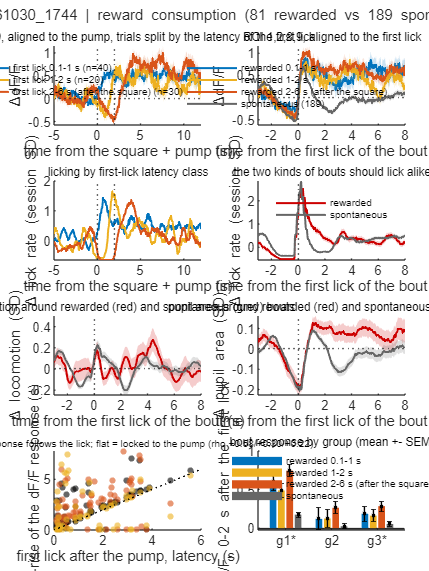


% figure 04
fh = newfig('Reward consumption', 18, 24);
tl = tiledlayout(fh, 4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
title(tl, sprintf('%s | reward consumption (%d rewarded vs %d spontaneous lick bouts)', strrep(session, '_', '\_'), nEv, nSp), 'FontSize', 9, 'FontWeight', 'normal');
a1 = nexttile(tl, 1);  hold(a1, 'on');  h1 = gobjects(1, 3);
for c = 1:3
    if sum(cls1 == c) >= 2; h1(c) = sem_trace(a1, tev, squeeze(Cg(1, :, cls1 == c)), cls_col(c, :), true); end
end
xline(a1, [0 lw(2)], ':');  yline(a1, 0, ':');  xlabel(a1, 'time from the square + pump (s)');  ylabel(a1, '\DeltadF/F');  xlim(a1, tev([1 end]));
ok_h = isgraphics(h1);  legend(a1, h1(ok_h), arrayfun(@(c) sprintf('first lick %s (n=%d)', cls_lab{c}, sum(cls1 == c)), find(ok_h), 'UniformOutput', false), 'FontSize', 6, 'Location', 'northeast');
title(a1, [grp_lab{1} ', aligned to the pump, trials split by the latency of the first lick'], 'FontSize', 7, 'FontWeight', 'normal');
a2 = nexttile(tl, 2);  hold(a2, 'on');  h2 = gobjects(1, 4);
for c = 1:3
    if sum(lat_cls == c) >= 2; h2(c) = sem_trace(a2, tb, squeeze(Rg(1, :, lat_cls == c)), cls_col(c, :), true); end
end
if nSp >= 2; h2(4) = sem_trace(a2, tb, squeeze(Sg(1, :, :)), [0.4 0.4 0.4], true); end
xline(a2, 0, ':');  yline(a2, 0, ':');  xlabel(a2, 'time from the first lick of the bout (s)');  ylabel(a2, '\DeltadF/F');  xlim(a2, tb([1 end]));
ok_h = isgraphics(h2);  l2 = [cellfun(@(s) ['rewarded ' s], cls_lab, 'UniformOutput', false), {sprintf('spontaneous (%d)', nSp)}];  legend(a2, h2(ok_h), l2(ok_h), 'FontSize', 6, 'Location', 'northeast');
title(a2, [grp_lab{1} ', aligned to the first lick'], 'FontSize', 7, 'FontWeight', 'normal');
a3 = nexttile(tl, 3);  hold(a3, 'on');
ilr = xi_('LickRate');  h3 = gobjects(1, 3);
for c = 1:3
    if sum(cls1 == c) >= 2; h3(c) = sem_trace(a3, tev, squeeze(Bal(ilr, :, cls1 == c)), cls_col(c, :), false); end
end
xline(a3, [0 lw(2)], ':');  xlabel(a3, 'time from the square + pump (s)');  ylabel(a3, '\Delta lick rate (session SD)');  xlim(a3, tev([1 end]));
title(a3, 'licking by first-lick latency class', 'FontSize', 7, 'FontWeight', 'normal');
a4 = nexttile(tl, 4);  hold(a4, 'on');  h4 = gobjects(1, 2);
if any(strcmp(xb_names, 'LickRate'))
    h4(1) = sem_trace(a4, tb, squeeze(Rb_(ilr, :, :)), [0.8 0 0], true);
    if nSp >= 2; h4(2) = sem_trace(a4, tb, squeeze(Sb_(ilr, :, :)), [0.4 0.4 0.4], true); end
end
xline(a4, 0, ':');  xlabel(a4, 'time from the first lick of the bout (s)');  ylabel(a4, '\Delta lick rate (session SD)');  xlim(a4, tb([1 end]));  legend(a4, h4(isgraphics(h4)), {'rewarded', 'spontaneous'}, 'FontSize', 6);
title(a4, 'the two kinds of bouts should lick alike', 'FontSize', 7, 'FontWeight', 'normal');
beh_show = intersect({'LocSpeed', 'PupilArea'}, xb_names, 'stable');
for q = 1:2
    a5 = nexttile(tl, 4 + q);  hold(a5, 'on');
    if q <= numel(beh_show)
        ib = xi_(beh_show{q});  hh = gobjects(1, 2);
        hh(1) = sem_trace(a5, tb, squeeze(Rb_(ib, :, :)), [0.8 0 0], true);
        if nSp >= 2; hh(2) = sem_trace(a5, tb, squeeze(Sb_(ib, :, :)), [0.4 0.4 0.4], true); end
        xline(a5, 0, ':');  yline(a5, 0, ':');  xlim(a5, tb([1 end]));  ylabel(a5, ['\Delta ' xb_lab{ib} ' (SD)']);  xlabel(a5, 'time from the first lick of the bout (s)');
        title(a5, [xb_lab{ib} ' around rewarded (red) and spontaneous (grey) bouts'], 'FontSize', 7, 'FontWeight', 'normal');
    end
end
a7 = nexttile(tl, 7);  hold(a7, 'on');
for g = 1:min(ng, 3)
    v = isfinite(th(g, :)') & isfinite(lat1);
    scatter(a7, lat1(v), th(g, v), 14, gcol(g, :), 'filled', 'MarkerFaceAlpha', 0.6);
end
plot(a7, [0 cons_max_s], [0 cons_max_s], 'k:');  xlabel(a7, 'first lick after the pump, latency (s)');  ylabel(a7, 'half-rise of the dF/F response (s)');  xlim(a7, [0 cons_max_s]);
title(a7, sprintf('dotted = response follows the lick; flat = locked to the pump (rho %s)', strjoin(arrayfun(@(g) sprintf('%+.2f', rho_th(g)), 1:min(ng, 3), 'UniformOutput', false), '/')), 'FontSize', 6, 'FontWeight', 'normal');
a8 = nexttile(tl, 8);  hold(a8, 'on');
Mbar = nan(ng, 4);  Ebar = Mbar;
for g = 1:ng
    for c = 1:3; v = A_rew(g, lat_cls == c); Mbar(g, c) = mean(v, 'omitnan'); Ebar(g, c) = std(v, 'omitnan') / sqrt(max(1, sum(isfinite(v)))); end
    Mbar(g, 4) = mean(A_sp(g, :), 'omitnan');  Ebar(g, 4) = std(A_sp(g, :), 'omitnan') / sqrt(max(1, nSp));
end
bh = bar(a8, [Mbar; nan(1, 4)], 'grouped');                                  % padded row: a single group would otherwise be drawn as one series
for c = 1:4
    if c < 4; bh(c).FaceColor = cls_col(c, :); else; bh(c).FaceColor = [0.4 0.4 0.4]; end
    bh(c).EdgeColor = 'none';
    errorbar(a8, bh(c).XEndPoints(1:ng), Mbar(:, c), Ebar(:, c), 'k.', 'CapSize', 3);
end
xlim(a8, [0.4 ng + 0.6]);
xticks(a8, 1:ng);  xticklabels(a8, arrayfun(@(g) sprintf('g%d%s', g, iff(grp_mot(g), '*', '')), 1:ng, 'UniformOutput', false));  ylabel(a8, sprintf('\\DeltadF/F, %g-%g s after the first lick', bout_win(1), bout_win(2)));
legend(a8, bh, [cellfun(@(s) ['rewarded ' s], cls_lab, 'UniformOutput', false), {'spontaneous'}], 'FontSize', 6, 'Location', 'best');
title(a8, 'bout response by group (mean +- SEM)', 'FontSize', 7, 'FontWeight', 'normal');

if save_figs; savef(fh, '04_reward_consumption'); end

## 11. Trial-by-trial regression and change over the session

% Per trial and group: amp = mean dF/F change in resp_win. Predictors (all z-scored): state before the square (mean over base_win), behaviour change in resp_win,
% licks in resp_win, hit, trial number. Coefficients with trial-bootstrap CIs. 'hit' and 'licks' ask: does consuming the reward go with a different response
% once locomotion, whisking, pupil, face motion and rigid shift are accounted for?
zs = @(x) (x - mean(x, 'omitnan')) ./ std(x, 'omitnan');
pre_b_ = reshape(mean(Braw(:, bi_, :), 2, 'omitnan'), nXB, nTr);
nl_resp = arrayfun(@(t) sum(lick_t >= on_t(t) + resp_win(1) & lick_t <= on_t(t) + resp_win(2)), (1:nTr)');
pred = {}; Xp = [];
if any(strcmp(xb_names, 'PupilArea'));  pred{end+1} = 'pre pupil';        Xp = [Xp, zs(pre_b_(xi_('PupilArea'), :)')]; end
if any(strcmp(xb_names, 'LocSpeed'));   pred{end+1} = 'pre locomotion';   Xp = [Xp, zs(pre_b_(xi_('LocSpeed'), :)')]; end
if any(strcmp(xb_names, 'WhiskIndex')); pred{end+1} = 'pre whisking';     Xp = [Xp, zs(pre_b_(xi_('WhiskIndex'), :)')]; end
if any(strcmp(xb_names, 'LocSpeed'));   pred{end+1} = 'evoked locomotion'; Xp = [Xp, zs(ev_beh(xi_('LocSpeed'), :)')]; end
if any(strcmp(xb_names, 'WhiskIndex')); pred{end+1} = 'evoked whisking';  Xp = [Xp, zs(ev_beh(xi_('WhiskIndex'), :)')]; end
if any(strcmp(xb_names, 'PupilArea'));  pred{end+1} = 'evoked pupil';     Xp = [Xp, zs(ev_beh(xi_('PupilArea'), :)')]; end
if have_motion;                         pred{end+1} = 'evoked rigid shift'; Xp = [Xp, zs(ev_beh(xi_('RigidShift'), :)')]; end
pred{end+1} = 'licks in resp\_win';  Xp = [Xp, zs(nl_resp)];
pred{end+1} = 'hit';                 Xp = [Xp, zs(double(hit))];
pred{end+1} = 'trial number';        Xp = [Xp, zs((1:nTr)')];
beta = nan(ngc, numel(pred) + 1);  beta_ci = nan(ngc, numel(pred) + 1, 2);  beta_p = beta;  r2_tr = nan(ngc, 1);
fprintf('\n11 trial regression: amp ~ %s\n', strjoin(strrep(pred, '\_', '_'), ' + '));


11 trial regression: amp ~ pre pupil + pre locomotion + pre whisking + evoked locomotion + evoked whisking + evoked pupil + evoked rigid shift + licks in resp_win + hit + trial number


for g = 1:ngc
    y_ = amp(g, :)';  X_ = [ones(nTr, 1), Xp];
    [b_, ci_, p_] = ols_boot(y_, X_, n_boot);
    beta(g, :) = b_';  beta_ci(g, :, :) = reshape(ci_, 1, numel(b_), 2);  beta_p(g, :) = p_';
    ok = all(isfinite([y_ X_]), 2);  r2_tr(g) = 1 - sum((y_(ok) - X_(ok, :) * b_) .^ 2) / sum((y_(ok) - mean(y_(ok))) .^ 2);
    fprintf('  %s (R2 %.2f): %s\n', glab_all{g}, r2_tr(g), strjoin(arrayfun(@(i) sprintf('%s %+.3f%s', strrep(pred{i}, '\_', '_'), b_(i + 1), iff(p_(i + 1) < 0.05, '*', '')), 1:numel(pred), 'UniformOutput', false), ', '));
    for i = [numel(pred) - 2, numel(pred) - 1, numel(pred)]
        ex = exadd(ex, ['11 trial regression, ' glab_all{g}], ['dF/F change per SD of ' strrep(pred{i}, '\_', '_') ' (other predictors held)'], b_(i + 1), sprintf('%s, bootstrap p=%.3f; model R2 %.2f', ci_str(ci_(i + 1, :)), p_(i + 1), r2_tr(g)), sum(ok));
    end
end

  ROI 1,2,8,9 (R2 0.79): pre pupil -0.123, pre locomotion +0.001, pre whisking +0.176, evoked locomotion +0.056, evoked whisking +0.479*, evoked pupil +0.073, evoked rigid shift -0.024, licks in resp_win +0.032, hit -0.064, trial number -0.062
  ROI 3,10 (R2 0.51): pre pupil -0.273, pre locomotion +0.049, pre whisking +0.302, evoked locomotion -0.021, evoked whisking +0.564*, evoked pupil +0.121, evoked rigid shift -0.118*, licks in resp_win -0.229*, hit -0.042, trial number -0.152*
  ROI 5,11 (R2 0.58): pre pupil -0.088, pre locomotion +0.069, pre whisking +0.071, evoked locomotion +0.062, evoked whisking +0.264*, evoked pupil +0.165*, evoked rigid shift -0.038, licks in resp_win -0.030, hit -0.087, trial number -0.058
  control: noise-like ROI 4,6,7 (R2 0.37): pre pupil +0.002, pre locomotion +0.017, pre whisking -0.019, evoked locomotion +0.007, evoked whisking -0.007, evoked pupil +0.038*, evoked rigid shift +0.016, licks in resp_win +0.017, hit +0.013, trial number -0.013


% change over the session
rho_tr = nan(ngc, 1);  p_tr = rho_tr;
for g = 1:ngc
    [rho_tr(g), p_tr(g)] = corr((1:nTr)', amp(g, :)', 'Type', 'Spearman', 'Rows', 'complete');
    mu_s = arrayfun(@(k) mean(amp(g, sub_of == k)), 1:nB);
    ex = exadd(ex, ['11 change over the session, ' glab_all{g}], 'Spearman: onset response vs trial number', rho_tr(g), sprintf('p=%.3g; subsession means %s', p_tr(g), mat2str(round(mu_s, 3))), nTr);
    fprintf('  %s: onset response vs trial number rho %+.2f (p=%.3g); subsession means %s\n', glab_all{g}, rho_tr(g), p_tr(g), mat2str(round(mu_s, 3)));
end

  ROI 1,2,8,9: onset response vs trial number rho -0.06 (p=0.561); subsession means [0.203 0.132 0.153]
  ROI 3,10: onset response vs trial number rho -0.12 (p=0.268); subsession means [0.059 0.104 -0.081]
  ROI 5,11: onset response vs trial number rho +0.01 (p=0.961); subsession means [0.093 0 0.076]
  control: noise-like ROI 4,6,7: onset response vs trial number rho -0.16 (p=0.144); subsession means [0.034 -0.006 -0.013]


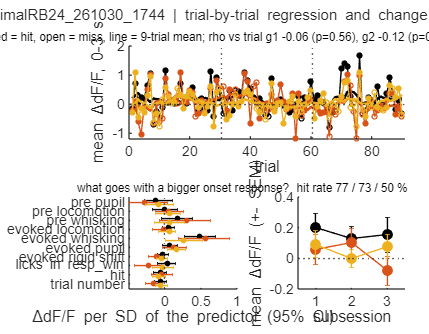

[rho_lt, p_lt] = corr((1:nTr)', lat1, 'Type', 'Spearman', 'Rows', 'complete');
ex = exadd(ex, '11 change over the session', 'Spearman: first-lick latency vs trial number', rho_lt, sprintf('p=%.3g', p_lt), sum(isfinite(lat1)));

fh = newfig('Trial regression', 18, 14);
tl = tiledlayout(fh, 2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
title(tl, [strrep(session, '_', '\_') ' | trial-by-trial regression and change over the session'], 'FontSize', 9, 'FontWeight', 'normal');
a1 = nexttile(tl, 1, [1 2]);  hold(a1, 'on');
for g = 1:ng
    plot(a1, 1:nTr, amp(g, :), '-', 'Color', [gcol(g, :) 0.3], 'LineWidth', 0.5);
    plot(a1, find(hit), amp(g, hit), 'o', 'Color', gcol(g, :), 'MarkerFaceColor', gcol(g, :), 'MarkerSize', 3);
    plot(a1, find(~hit), amp(g, ~hit), 'o', 'Color', gcol(g, :), 'MarkerSize', 3);
    plot(a1, 1:nTr, movmean(amp(g, :), 9, 'omitnan'), '-', 'Color', gcol(g, :), 'LineWidth', 1.5);
end
xline(a1, (1:nB - 1) * S.trials + 0.5, ':');  yline(a1, 0, ':');  xlabel(a1, 'trial');  ylabel(a1, sprintf('mean \\DeltadF/F, %g-%g s', resp_win(1), resp_win(2)));  xlim(a1, [0 nTr + 1]);
title(a1, sprintf('filled = hit, open = miss, line = 9-trial mean; rho vs trial %s', strjoin(arrayfun(@(g) sprintf('g%d %+.2f (p=%.2g)', g, rho_tr(g), p_tr(g)), 1:ng, 'UniformOutput', false), ', ')), 'FontSize', 7, 'FontWeight', 'normal');
a2 = nexttile(tl, 3);  hold(a2, 'on');
np_ = numel(pred);  dy = 0.8 / ng;
for g = 1:ng
    yy = (1:np_) + (g - (ng + 1) / 2) * dy / 1.5;
    errorbar(a2, beta(g, 2:end), yy, beta(g, 2:end) - squeeze(beta_ci(g, 2:end, 1)), squeeze(beta_ci(g, 2:end, 2)) - beta(g, 2:end), 'horizontal', 'o', 'Color', gcol(g, :), 'MarkerFaceColor', gcol(g, :), 'MarkerSize', 3, 'CapSize', 2);
end
xline(a2, 0, ':');  yticks(a2, 1:np_);  yticklabels(a2, pred);  set(a2, 'YDir', 'reverse');  ylim(a2, [0.4 np_ + 0.6]);  xlabel(a2, '\DeltadF/F per SD of the predictor (95% CI)');
title(a2, 'what goes with a bigger onset response?', 'FontSize', 7, 'FontWeight', 'normal');
a3 = nexttile(tl, 4);  hold(a3, 'on');
for g = 1:ng
    mu_s = arrayfun(@(k) mean(amp(g, sub_of == k)), 1:nB);  se_s = arrayfun(@(k) std(amp(g, sub_of == k)) / sqrt(S.trials), 1:nB);
    errorbar(a3, 1:nB, mu_s, se_s, 'o-', 'Color', gcol(g, :), 'MarkerFaceColor', gcol(g, :), 'CapSize', 3);
end
yline(a3, 0, ':');  xticks(a3, 1:nB);  xlim(a3, [0.5 nB + 0.5]);  xlabel(a3, 'subsession');  ylabel(a3, 'mean \DeltadF/F (+- SEM)');
title(a3, sprintf('hit rate %s %%', strjoin(arrayfun(@(x) sprintf('%.0f', x), sub_tbl.hit_pct', 'UniformOutput', false), ' / ')), 'FontSize', 7, 'FontWeight', 'normal');

if save_figs; savef(fh, '05_trial_regression'); end

## 12. Correlation of ROI activity with behaviour over the session

% Behaviour: pupil, whisking, face motion, eyelid, locomotion, lick rate (+ suite2p rigid shift). 1 s smoothing, 5 Hz. Per ROI and behaviour: r at lag 0 and at the
% best lag within +- corr_max_lag_s (positive lag = ROI follows the behaviour). Null: behaviour circularly shifted by >= 30 s; p = rank of |r_best| among the max |r| over lags.
% The epoch is the three subsessions (the 2-min breaks are left out). Computed for all ROIs; the figure shows sel_roi.
cb_names = xb_names;  cb_lab = cellfun(@(n) beh_short.(n), xb_names, 'UniformOutput', false);
ncb = numel(cb_names);
ds_ = max(1, round(fs / 5));  fs5 = fs / ds_;  t5 = tCa(1:ds_:end);
Xs5 = movmean(dFFd, round(fs), 2);  Xs5 = Xs5(:, 1:ds_:end);
Y5  = nan(ncb, numel(t5));
for si = 1:ncb
    if strcmp(cb_names{si}, 'RigidShift'); yy = movmean(rigid, round(fs)); else; yy = movmean(beh_ca.(cb_names{si}), round(fs), 'omitnan'); end
    Y5(si, :) = yy(1:ds_:end);
end
L5 = round(corr_max_lag_s * fs5);  lags5 = -L5:L5;
seg = zeros(0, 2);  ix_all = [];
for k = 1:nB
    ii = find(t5 >= b_t0(k) & t5 <= b_t1(k));
    seg(end+1, :) = [numel(ix_all) + 1, numel(ix_all) + numel(ii)];  ix_all = [ix_all, ii]; %#ok<AGROW>
end
n_e = numel(ix_all);
Xe = Xs5(:, ix_all);  Xe = (Xe - mean(Xe, 2)) ./ std(Xe, 0, 2);
Ye = Y5(:, ix_all);
shift_min = min(round(30 * fs5), floor(0.25 * n_e));
coup_r = nan(nROI, ncb);  coup_r0 = coup_r;  coup_lag = coup_r;  coup_p = coup_r;
for si = 1:ncb
    y = Ye(si, :);
    if mean(isfinite(y)) < 0.7; continue; end
    y = (y - mean(y, 'omitnan')) / std(y, 'omitnan');  y(~isfinite(y)) = 0;
    obs = xc_lags(Xe, y, seg, lags5);
    [~, bi_c] = max(abs(obs), [], 2);
    coup_r(:, si) = obs(sub2ind(size(obs), (1:nROI)', bi_c));  coup_lag(:, si) = lags5(bi_c) / fs5;  coup_r0(:, si) = obs(:, lags5 == 0);
    nul = zeros(nROI, n_perm);
    for p = 1:n_perm; nul(:, p) = max(abs(xc_lags(Xe, circshift(y, randi([shift_min, n_e - shift_min])), seg, lags5)), [], 2); end
    coup_p(:, si) = (1 + sum(nul >= abs(coup_r(:, si)), 2)) / (n_perm + 1);
end
beh_cc = corrcoef(Ye', 'Rows', 'pairwise');
nl_ = noise_like & ~bad_F;
for si = 1:ncb
    if all(isnan(coup_p(:, si))); continue; end
    cp = coup_p(:, si);
    chk = addchk(chk, ['coupling: ' cb_names{si}], grade(~(any(nl_) && mean(cp(nl_) < 0.01) > 0.5), 1), sprintf('%d/%d ROIs coupled (p < 0.01, best lag within +-%g s), signal-like %d/%d, noise-like %d/%d; median |r| %.2f. WARN = the flat ROIs follow it too (common cause: motion / neuropil / arousal)', sum(cp < 0.01), nROI, corr_max_lag_s, sum(cp < 0.01 & signal_like), sum(signal_like), sum(cp < 0.01 & nl_), sum(nl_), median(abs(coup_r(:, si)), 'omitnan')));
end
[Ri, Bi] = ndgrid(1:nROI, 1:ncb);
vv = ~isnan(coup_r(:));
cbn_ = cb_names(:);
corr_tbl = table(Ri(vv), ismember(Ri(vv), sel_roi), cbn_(Bi(vv)), coup_r0(vv), coup_r(vv), coup_lag(vv), coup_p(vv), 'VariableNames', {'roi', 'selected', 'behaviour', 'r_lag0', 'r_best', 'lag_s', 'p'});
if ~isempty(corr_tbl); disp(groupsummary(corr_tbl(corr_tbl.selected, :), 'behaviour', {'median', 'median'}, {'r_best', 'lag_s'})); end

        behaviour        GroupCount    median_r_best    median_lag_s
    _________________    __________    _____________    ____________

    {'EyeLidOpening'}        8             0.1549         -0.70002  
    {'FacePadME'    }        8            0.47993              0.1  
    {'LickRate'     }        8            0.47615          0.40001  
    {'LocSpeed'     }        8            0.18221                0  
    {'PupilArea'    }        8             0.1694         -0.60002  
    {'RigidShift'   }        8            0.34558          0.20001  
    {'WhiskIndex'   }        8            0.55063              0.1  



printchk(chk, n0);  n0 = size(chk, 1);

  [PASS] onset response: pseudo-onsets        252 pseudo-onsets from 42 trials with a wait long enough (baseline >= 5 s after the trial start); the null for the 90 real onsets is built from them
  [WARN] coupling: PupilArea                  11/11 ROIs coupled (p < 0.01, best lag within +-3 s), signal-like 8/8, noise-like 3/3; median |r| 0.17. WARN = the flat ROIs follow it too (common cause: motion / neuropil / arousal)
  [WARN] coupling: WhiskIndex                 11/11 ROIs coupled (p < 0.01, best lag within +-3 s), signal-like 8/8, noise-like 3/3; median |r| 0.52. WARN = the flat ROIs follow it too (common cause: motion / neuropil / arousal)
  [WARN] coupling: FacePadME                  11/11 ROIs coupled (p < 0.01, best lag within +-3 s), signal-like 8/8, noise-like 3/3; median |r| 0.45. WARN = the flat ROIs follow it too (common cause: motion / neuropil / arousal)
  [WARN] coupling: EyeLidOpening              11/11 ROIs coupled (p < 0.01, best lag within +-3 s), signal-like 8/8, n

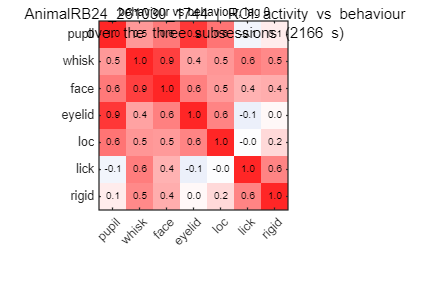

h1_ = max(3.5, 0.25 * nSel);  FH = 1.3 + h1_ + 1.5 + 4.0 + 1.5;  FW = 18;
fh = newfig('Behaviour correlation', FW, FH);
ax1 = axes('Units', 'centimeters', 'Position', [2.1, FH - 1.3 - h1_, 6.5, h1_]);
imagesc(coup_r(sel_roi, :));  clim([-0.8 0.8]);  colormap(ax1, div_cmap);  hold on;
[sr, sc] = find(coup_p(sel_roi, :) < 0.01);  plot(sc, sr, 'k*', 'MarkerSize', 3);
xticks(1:ncb);  xticklabels(cb_lab);  xtickangle(45);  yticks(1:roi_skip:nSel);  yticklabels(roi_lab(1:roi_skip:nSel));  ylabel('ROI');
cb = colorbar(ax1);  cb.Label.String = 'r at best lag (* p < 0.01)';  cb.FontSize = 7;  set(ax1, 'Units', 'centimeters', 'Position', [2.1, FH - 1.3 - h1_, 6.5, h1_]);
ax2 = axes('Units', 'centimeters', 'Position', [11.2, FH - 1.3 - h1_, 5.5, h1_]);
imagesc(coup_lag(sel_roi, :));  clim([-corr_max_lag_s corr_max_lag_s]);  colormap(ax2, div_cmap);  xticks(1:ncb);  xticklabels(cb_lab);  xtickangle(45);  yticks([]);
cb = colorbar(ax2);  cb.Label.String = 'best lag (s), positive = ROI follows';  cb.FontSize = 7;  set(ax2, 'Units', 'centimeters', 'Position', [11.2, FH - 1.3 - h1_, 5.5, h1_]);
ax3 = axes('Units', 'centimeters', 'Position', [2.1, 1.5, 4.0, 4.0]);
imagesc(beh_cc);  clim([-1 1]);  colormap(ax3, div_cmap);  hold on;
for a = 1:ncb; for b = 1:ncb; if isfinite(beh_cc(a, b)); text(b, a, sprintf('%.1f', beh_cc(a, b)), 'HorizontalAlignment', 'center', 'FontSize', 6); end; end; end
xticks(1:ncb);  xticklabels(cb_lab);  xtickangle(45);  yticks(1:ncb);  yticklabels(cb_lab);  title('behaviour vs behaviour, lag 0', 'FontWeight', 'normal', 'FontSize', 7);
annotation(fh, 'textbox', [0, 1 - 0.55 / FH, 1, 0.5 / FH], 'String', sprintf('%s | ROI activity vs behaviour over the three subsessions (%.0f s)', strrep(session, '_', '\_'), n_e / fs5), 'EdgeColor', 'none', 'HorizontalAlignment', 'center', 'FontName', 'Arial', 'FontSize', 9);

if save_figs; savef(fh, '06_behaviour_correlation'); end

## C. Extra diagnostic figures (extra_figs = true)

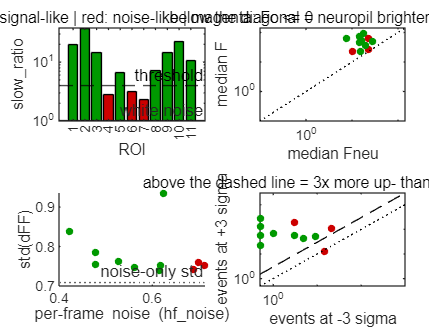

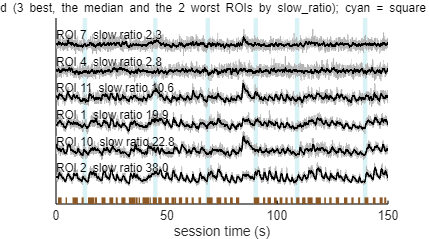

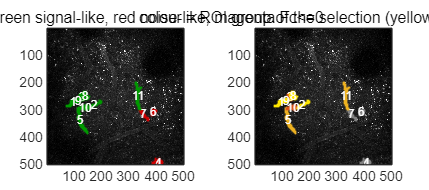

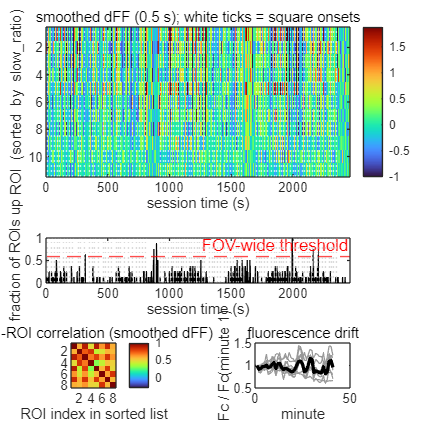

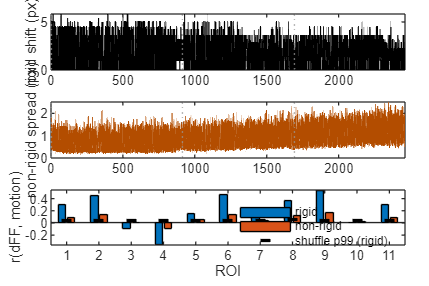

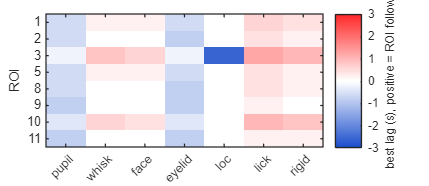

if extra_figs
    % C1 ROI signal quality
    cl = zeros(nROI, 3);  cl(signal_like, 2) = 0.6;  cl(noise_like & ~bad_F, 1) = 0.8;  cl(bad_F, :) = repmat([0.7 0 0.7], sum(bad_F), 1);
    fh = newfig('ROI signal quality', 18, 14);
    tiledlayout(fh, 2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    nexttile;  b = bar(slow_ratio, 'FaceColor', 'flat');  b.CData = cl;  set(gca, 'YScale', 'log');  yline(slow_ratio_thr, 'k--', 'threshold');  yline(1, ':', 'white noise');
    xlabel('ROI');  ylabel('slow\_ratio');  title('green: signal-like | red: noise-like | magenta: Fc <= 0', 'FontWeight', 'normal');
    nexttile;  loglog(max(median(Fneu, 2), 0.1), max(median(F, 2), 0.1), '.', 'MarkerSize', 1);  hold on;  scatter(max(median(Fneu, 2), 0.1), max(median(F, 2), 0.1), 20, cl, 'filled');
    lim = [0.1 max([median(F, 2); median(Fneu, 2)]) * 1.5];  plot(lim, lim, 'k:');  xlabel('median Fneu');  ylabel('median F');  title('below the diagonal = neuropil brighter than ROI', 'FontWeight', 'normal');
    nexttile;  scatter(hf_noise, std(dFF, 0, 2), 20, cl, 'filled');  hold on;  yline(0.71, ':', 'noise-only std');  xlabel('per-frame noise (hf\_noise)');  ylabel('std(dFF)');
    nexttile;  loglog(max(ev_neg, 0.5), max(ev_pos, 0.5), '.', 'MarkerSize', 1);  hold on;  scatter(max(ev_neg, 0.5), max(ev_pos, 0.5), 20, cl, 'filled');
    plot([0.5 1e3], [0.5 1e3], 'k:');  plot([0.5 1e3], 3*[0.5 1e3], 'k--');  xlabel('events at -3 sigma');  ylabel('events at +3 sigma');  title('above the dashed line = 3x more up- than down-events', 'FontWeight', 'normal');
    if save_figs; savef(fh, 'C1_roi_quality'); end

    % C2 example traces: best, median and worst ROIs by slow_ratio, first 150 s of the session with squares and licks
    ex_t0 = tr_t0(1);  iw_ = tCa >= ex_t0 & tCa <= ex_t0 + 150;
    [~, ord] = sort(slow_ratio, 'descend');
    ex_rois = unique(ord([1 2 3 round(nROI/2) max(1, nROI-1) nROI])', 'stable');
    fh = newfig('Example ROI traces', 18, 10);  hold on;
    for k = find(on_t' >= ex_t0 & on_t' <= ex_t0 + 150); patch([on_t(k) st_end(k) st_end(k) on_t(k)], [0 0 numel(ex_rois) + 1 numel(ex_rois) + 1], col.sq, 'FaceAlpha', 0.15, 'EdgeColor', 'none'); end
    for j = 1:numel(ex_rois)
        r = ex_rois(j);
        plot(tCa(iw_), double(dFF(r, iw_)) / 6 + j, 'Color', [0.7 0.7 0.7]);
        plot(tCa(iw_), double(dsm(r, iw_)) / 6 + j, 'k', 'LineWidth', 1);
        text(tCa(find(iw_, 1)), j + 0.35, sprintf('ROI %d  slow ratio %.1f', r, slow_ratio(r)), 'FontSize', 7);
    end
    lk_ = lick_t(lick_t >= ex_t0 & lick_t <= ex_t0 + 150);
    plot(repmat(lk_', 2, 1), repmat([0; 0.25], 1, numel(lk_)), 'Color', col.lick, 'LineWidth', 0.4);
    yticks([]);  xlabel('session time (s)');  title('grey: dFF, black: smoothed (3 best, the median and the 2 worst ROIs by slow\_ratio); cyan = square + pump, brown ticks = licks', 'FontWeight', 'normal', 'FontSize', 7);
    if save_figs; savef(fh, 'C2_example_traces'); end

    % C3 ROI map on the max projection
    if has_img
        fh = newfig('ROI map', 18, 8);
        tiledlayout(fh, 1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
        for pnl = 1:2
            nexttile;  imagesc(im);  axis image;  colormap(gca, gray);  clim(prctile(im(:), [1 99.8]));  hold on;
            for j = 1:numel(pl_rois)
                r = pl_rois(j);
                if pnl == 1; c = cl(r, :); elseif ismember(r, sel_roi); c = gcol(gid(sel_roi == r), :); if all(c == 0); c = [1 0.9 0]; end; else; c = [0.5 0.5 0.5]; end
                plot(xp{j} + 1 + off(2), yp{j} + 1 + off(1), '.', 'Color', c, 'MarkerSize', 2);
                if nROI <= 80; text(cent(r, 2) + 1 + off(2), cent(r, 1) + 1 + off(1), sprintf('%d', r), 'Color', 'w', 'FontSize', 7, 'HorizontalAlignment', 'center'); end
            end
            if pnl == 1; title(sprintf('shift [%d %d]; green signal-like, red noise-like, magenta Fc<=0', off(1), off(2)), 'FontWeight', 'normal'); else; title('colour = ROI group of the selection (yellow = group 1)', 'FontWeight', 'normal'); end
        end
        if save_figs; savef(fh, 'C3_roi_map'); end
    end

    % C4 population: heatmap, FOV-wide events, ROI-ROI correlation, drift
    fh = newfig('Population', 18, 18);
    tiledlayout(fh, 4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    [~, so2] = sort(slow_ratio, 'descend');  show = so2(1:min(nROI, 200));
    nexttile([2 2]);  imagesc(tCa, 1:numel(show), double(dsm(show, :)));  clim([-1 max(prctile(double(dsm(:)), 99.7), 1)]);  colormap(gca, turbo);  colorbar;
    ylabel('ROI (sorted by slow\_ratio)');  xlabel('session time (s)');  title(sprintf('smoothed dFF (%.1f s); white ticks = square onsets', smooth_s), 'FontWeight', 'normal');  xline(on_t, 'w:');
    nexttile([1 2]);  plot(tCa, co, 'k');  hold on;  yline(co_thr, 'r--', 'FOV-wide threshold');  ylabel('fraction of ROIs up');  xlabel('session time (s)');  xlim([tCa(1) tCa(end)]);  xline(on_t, 'Color', [0.8 0.8 0.8], 'LineStyle', ':');
    nexttile;  imagesc(Cm);  axis image;  clim([-0.3 1]);  colormap(gca, turbo);  colorbar;  title('ROI-ROI correlation (smoothed dFF)', 'FontWeight', 'normal');  xlabel('ROI index in sorted list');
    nexttile;  plot(1:nb, Fb_rel', 'Color', [0.6 0.6 0.6]);  hold on;  plot(1:nb, median(Fb_rel, 1, 'omitnan'), 'k', 'LineWidth', 2);  xlabel('minute');  ylabel('Fc / Fc(minute 1)');  title('fluorescence drift', 'FontWeight', 'normal');
    if save_figs; savef(fh, 'C4_population'); end

    % C5 motion
    if have_motion
        fh = newfig('Motion', 18, 12);
        tiledlayout(fh, 3, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
        nexttile;  plot(tCa, rigid, 'k');  ylabel('rigid shift (px)');  xlim([tCa(1) tCa(end)]);  xline(b_t0, 'Color', [0.6 0.6 0.6], 'LineStyle', ':');
        nexttile;  plot(tCa, nonr, 'Color', [0.7 0.3 0]);  ylabel('non-rigid spread (px)');  xlim([tCa(1) tCa(end)]);  xline(b_t0, 'Color', [0.6 0.6 0.6], 'LineStyle', ':');
        nexttile;  bar([motion_r(:, 1) motion_r(:, 2)]);  hold on;  plot(thr99(:, 1), 'k_', 'LineWidth', 2);  ylabel('r(dFF, motion)');  xlabel('ROI');  legend([mot_names, {'shuffle p99 (rigid)'}]);
        if save_figs; savef(fh, 'C5_motion'); end
    end

    % C6 best lag of the behaviour correlations
    fh = newfig('Correlation lags', 12, 4 + 0.15 * nSel);
    imagesc(coup_lag(sel_roi, :));  clim([-corr_max_lag_s corr_max_lag_s]);  colormap(gca, div_cmap);
    xticks(1:ncb);  xticklabels(cb_lab);  xtickangle(45);  yticks(1:roi_skip:nSel);  yticklabels(roi_lab(1:roi_skip:nSel));  ylabel('ROI');
    cb = colorbar;  cb.Label.String = 'best lag (s), positive = ROI follows';  cb.FontSize = 7;
    if save_figs; savef(fh, 'C6_correlation_lags'); end
end

## 13. Summary

fprintf('\n================ axon_analysis_task_analysis_V1 summary: %s ================\n', session);


================ axon_analysis_task_analysis_V1 summary: AnimalRB24_261030_1744 ================


cellfun(@(a, b, d) fprintf('[%s] %-36s %s\n', b, a, d), chk(:, 1), chk(:, 2), chk(:, 3));

[PASS] file: core variables                 4/4 present 
[PASS] file: training stimulus struct       1 Stimuli struct(s), type training, Training 1, lickData 1, FrameValid 1. This script needs ONE training struct with lick data and per-trial frame validity (newAggregation 2026-11-01 or later)
[PASS] file: optional variables             Behav 1, Locomotion 1, Img_max 1, SI_Info 1
[PASS] CaData: populated entry              CaData(1) has traces, 1 of 3 entries populated
[PASS] Ca arrays: same size                 dFF/F/Fneu/baseline/deconvolved: 11 ROIs x 73837 frames
[PASS] TimeCa: matches frames               73837 time stamps, 73837 frames
[PASS] ROI bookkeeping                      11 centroids, 11 cellstats
[PASS] dFF: finite                          0.0000% NaN/Inf
[PASS] planes                               1 plane(s); TimeCa has 1 row(s); row 1 is used as common time base
[PASS] Behav: rows == camera triggers       123021 camera triggers, 34 Behav fields
[PASS] VideoParams: frame

fprintf('\n%d PASS, %d WARN, %d FAIL\n', sum(strcmp(chk(:, 2), 'PASS')), sum(strcmp(chk(:, 2), 'WARN')), sum(strcmp(chk(:, 2), 'FAIL')));


53 PASS, 14 WARN, 0 FAIL


fprintf('Candidate ROIs for analysis (signal-like, no Fc<=0, not motion-coupled): %s\n', lst(good_roi));

Candidate ROIs for analysis (signal-like, no Fc<=0, not motion-coupled): [3 10]


fprintf('Selected ROIs used for the figures (roi_sel): %s; groups: %s\n', lst(sel_roi), strjoin(grp_lab, ' | '));

Selected ROIs used for the figures (roi_sel): [1 2 3 5 8 9 10 11]; groups: ROI 1,2,8,9 | ROI 3,10 | ROI 5,11


qc_table = cell2table(chk, 'VariableNames', {'check', 'status', 'detail'});
if save_figs
    writetable(roiq, fullfile(fig_dir, 'roi_quality.csv'));
    writetable(qc_table, fullfile(fig_dir, 'checks.csv'));
    writetable(corr_tbl, fullfile(fig_dir, 'behaviour_correlation.csv'));
    writetable(trl, fullfile(fig_dir, 'trials.csv'));
end

## 14. Encoding model: what do the square + pump, the consumption and the arousal state each add?


14 encoding model: 3 groups, 9 families, 101 regressors, 3 held-out subsessions


  ROI 1,2,8,9: held-out R2 of the full model 0.45; unique R2: square + pump -0.000 (p=0.20), first lick +0.002 (p=0.02), spont. bout +0.010 (p=0.02), lick rate +0.037, whisking +0.009, pupil +0.021, face motion +0.003, locomotion +0.011, rigid shift -0.008
  ROI 3,10: held-out R2 of the full model 0.27; unique R2: square + pump -0.001 (p=0.41), first lick +0.000 (p=0.10), spont. bout +0.008 (p=0.02), lick rate +0.021, whisking +0.009, pupil +0.019, face motion +0.008, locomotion +0.006, rigid shift +0.005
  ROI 5,11: held-out R2 of the full model 0.15; unique R2: square + pump -0.001 (p=0.54), first lick +0.001 (p=0.05), spont. bout +0.009 (p=0.02), lick rate +0.002, whisking +0.003, pupil +0.017, face motion +0.007, locomotion -0.003, rigid shift -0.006


  ROI 1,2,8,9 kernels (in-sample, dF/F per event): square + pump 0-3 s -0.109; first lick 0-2 s +0.042; spontaneous bout 0-2 s -0.074
  ROI 3,10 kernels (in-sample, dF/F per event): square + pump 0-3 s -0.146; first lick 0-2 s +0.047; spontaneous bout 0-2 s -0.010
  ROI 5,11 kernels (in-sample, dF/F per event): square + pump 0-3 s -0.091; first lick 0-2 s +0.030; spontaneous bout 0-2 s -0.035


  [PASS] encoding model: events resolvable    81 trials with a rewarded bout, latency to the pump 2.28 +- 1.36 s (SD): the square + pump and first-lick regressors are separable only through this jitter


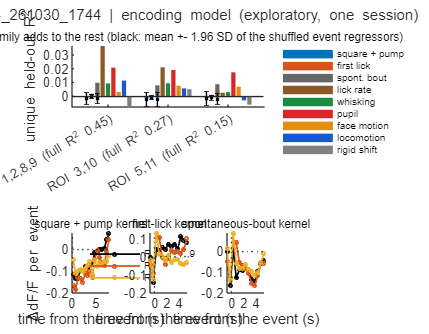

% Leave-one-subsession-out ridge regression of every ROI group's dF/F (30 Hz) on families of regressors, each a set of 0.5 s boxcar lags:
%   square + pump  : impulse at the square onset, lags 0 to 8 s
%   first lick     : impulse at the first lick of the first isolated bout after the pump (the consumption), lags -1 to +5.5 s
%   spont. bout    : impulse at spontaneous (unrewarded) lick bouts of the wait period, same lags
%   lick rate, whisking, pupil, face motion, locomotion, rigid shift : continuous, lags -1 to +4 s (lick rate -1 to +3 s)
% 'Unique' R^2 of a family = held-out R^2 of the full model minus that of the model without it. Because the licking starts 0.1 to ~5 s after the pump, the
% square + pump and first-lick regressors are not collinear, so the model can say which one the data need. Nulls (n_null shuffles, p resolution 1/(n_null+1)):
%   square + pump : onsets shifted inside their subsession (spacing kept, timing against the data destroyed)
%   first lick    : the latencies shuffled between trials (first-lick regressor at the wrong time after the pump, lick-rate regressor untouched)
%   spont. bout   : bout onsets shifted inside their subsession
if explore_stats
    rng(3);
    wb  = round(0.5 * fs);
    Yg  = grp_mean';                                                                  % [nT x ng]
    blk_f = zeros(nT, 1);  for k = 1:nB; blk_f(tCa >= b_t0(k) & tCa <= b_t1(k)) = k; end
    zf  = @(x) fillmissing((x - mean(x, 'omitnan')) / std(x, 'omitnan'), 'constant', 0);
    fam_names = {'square + pump', 'first lick', 'spont. bout', 'lick rate'};
    fam_js    = {0:15, -2:10, -2:10, -2:6};
    fam_cont  = {'lick rate', 'LickRate'; 'whisking', 'WhiskIndex'; 'pupil', 'PupilArea'; 'face motion', 'FacePadME'; 'locomotion', 'LocSpeed'; 'rigid shift', 'RigidShift'};
    Xcont = cell(1, 0);
    for q = 1:size(fam_cont, 1)
        ii = find(strcmp(xb_names, fam_cont{q, 2}), 1);
        if isempty(ii); continue; end
        js_ = -2:7;  if q == 1; js_ = -2:6; end
        Xcont{end+1} = box_lags(zf(XB(ii, :)), js_, wb); %#ok<SAGROW>
        if q > 1; fam_names{end+1} = fam_cont{q, 1}; end %#ok<SAGROW>
    end
    nF = numel(fam_names);
    mk_ev = @(on_, co_, sp_) {event_reg(on_, tCa, fam_js{1}, wb), event_reg(co_, tCa, fam_js{2}, wb), event_reg(sp_, tCa, fam_js{3}, wb)};
    ev0 = mk_ev(on_t(:)', cons_on(:)', sp_on(:)');
    Xfam = [ev0, Xcont];                                                              % families in the order of fam_names
    cvr2 = @(Xc) cv_r2(Yg, Xc, blk_f, 0.05);
    fprintf('\n14 encoding model: %d groups, %d families, %d regressors, %d held-out subsessions\n', ng, nF, sum(cellfun(@(x) size(x, 2), Xfam)), nB);
    r2_full = cvr2(Xfam);
    r2_drop = nan(nF, ng);
    for f = 1:nF; r2_drop(f, :) = cvr2(Xfam([1:f-1, f+1:nF])); end
    d_uni = r2_full - r2_drop;                                                        % [nF x ng] unique held-out R^2
    % nulls for the three event families
    dnull = nan(n_null, 3, ng);
    kk = find(isfinite(cons_on));
    for it = 1:n_null
        on_n = shift_in_blocks(on_t(:)', b_t0, b_t1);
        co_n = cons_on(:)';  co_n(kk) = on_t(kk)' + cons_lat(kk(randperm(numel(kk))))';
        sp_n = shift_in_blocks(sp_on(:)', b_t0, b_t1);
        evn = mk_ev(on_n, co_n, sp_n);
        for f = 1:3
            Xn = Xfam;  Xn{f} = evn{f};
            dnull(it, f, :) = reshape(cvr2(Xn) - r2_drop(f, :), 1, 1, ng);
        end
    end
    p_ev = nan(3, ng);
    for f = 1:3; for g = 1:ng; p_ev(f, g) = (1 + sum(dnull(:, f, g) >= d_uni(f, g))) / (n_null + 1); end; end
    for g = 1:ng
        fs_ = cell(1, nF);
        for f = 1:nF
            fs_{f} = sprintf('%s %+.3f', fam_names{f}, d_uni(f, g));
            if f <= 3; fs_{f} = sprintf('%s (p=%.2f)', fs_{f}, p_ev(f, g)); end
        end
        fprintf('  %s: held-out R2 of the full model %.2f; unique R2: %s\n', grp_lab{g}, r2_full(g), strjoin(fs_, ', '));
        ex = exadd(ex, ['14 encoding model, ' grp_lab{g}], 'held-out R2 of the full model', r2_full(g), '', sum(blk_f > 0));
        for f = 1:nF
            if f <= 3; pstr = sprintf('shuffle null %+.3f+-%.3f, p=%.2f', mean(dnull(:, f, g)), std(dnull(:, f, g)), p_ev(f, g)); else; pstr = ''; end
            ex = exadd(ex, ['14 encoding model, ' grp_lab{g}], ['unique held-out R2: ' fam_names{f}], d_uni(f, g), pstr, sum(blk_f > 0));
        end
    end

    % kernels from a fit on all data (in-sample; ridge on standardised columns, coefficients converted to dF/F per indicator)
    Xall = cell2mat(Xfam);  Xall(isnan(Xall)) = 0;  okk = blk_f > 0;
    mu_x = mean(Xall(okk, :), 1);  sd_x = std(Xall(okk, :), 0, 1);  sd_x(sd_x == 0) = 1;
    Xz = (Xall(okk, :) - mu_x) ./ sd_x;  ym = mean(Yg(okk, :), 1);
    Bk = (Xz' * Xz + 0.05 * nnz(okk) * eye(size(Xz, 2))) \ (Xz' * (Yg(okk, :) - ym));
    Bk = Bk ./ sd_x';
    c0 = [0, cumsum(cellfun(@(x) size(x, 2), Xfam))];
    kern = cell(1, 3);  tk = cell(1, 3);
    for f = 1:3
        kern{f} = Bk(c0(f) + 1:c0(f + 1), :);  tk{f} = (fam_js{f} + 0.5) * wb / fs;
    end
    % amplitude of the kernels: mean over the lag bins that matter (square: 0-3 s, first lick: 0-2 s), against the bins before
    for g = 1:ng
        k1 = kern{1}(tk{1} >= 0 & tk{1} <= resp_win(2), g);  k2 = kern{2}(tk{2} >= 0 & tk{2} <= 2, g);  k3 = kern{3}(tk{3} >= 0 & tk{3} <= 2, g);
        fprintf('  %s kernels (in-sample, dF/F per event): square + pump %g-%g s %+.3f; first lick 0-2 s %+.3f; spontaneous bout 0-2 s %+.3f\n', grp_lab{g}, 0, resp_win(2), mean(k1), mean(k2), mean(k3));
        ex = exadd(ex, ['14 kernels, ' grp_lab{g}], sprintf('square + pump kernel, mean 0-%g s (dF/F, in-sample)', resp_win(2)), mean(k1), '', nTr);
        ex = exadd(ex, ['14 kernels, ' grp_lab{g}], 'first-lick kernel, mean 0-2 s (dF/F, in-sample)', mean(k2), '', numel(kk));
        ex = exadd(ex, ['14 kernels, ' grp_lab{g}], 'spontaneous-bout kernel, mean 0-2 s (dF/F, in-sample)', mean(k3), '', nSp);
    end
    chk = addchk(chk, 'encoding model: events resolvable', grade(std(cons_lat(kk)) > 0.5, 1), sprintf('%d trials with a rewarded bout, latency to the pump %.2f +- %.2f s (SD): the square + pump and first-lick regressors are separable only through this jitter', numel(kk), mean(cons_lat(kk)), std(cons_lat(kk))));
    printchk(chk, n0);  n0 = size(chk, 1);

    % figure 07
    fcols = [0 0.45 0.74; 0.85 0.33 0.1; 0.4 0.4 0.4; 0.55 0.35 0.15; 0.1 0.55 0.25; 0.85 0.15 0.15; 0.9 0.55 0.05; 0.1 0.35 0.8; 0.5 0.5 0.5];
    fh = newfig('Encoding model', 18, 14);
    tl = tiledlayout(fh, 2, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(tl, [strrep(session, '_', '\_') ' | encoding model (exploratory, one session)'], 'FontSize', 9, 'FontWeight', 'normal');
    a1 = nexttile(tl, 1, [1 3]);  hold(a1, 'on');
    bd = bar(a1, [d_uni'; nan(1, nF)], 'grouped');                                % padded row: a single group would otherwise be drawn as one series
    for f = 1:nF
        bd(f).FaceColor = fcols(f, :);  bd(f).EdgeColor = 'none';
        if f <= 3; errorbar(a1, bd(f).XEndPoints(1:ng), squeeze(mean(dnull(:, f, :), 1))', 1.96 * squeeze(std(dnull(:, f, :), 0, 1))', 'k.', 'CapSize', 3, 'MarkerSize', 6); end
    end
    yline(a1, 0, '-');  xlim(a1, [0.4 ng + 0.6]);  xticks(a1, 1:ng);  xticklabels(a1, arrayfun(@(g) sprintf('%s (full R^2 %.2f)', grp_lab{g}, r2_full(g)), 1:ng, 'UniformOutput', false));
    ylabel(a1, 'unique held-out R^2');  legend(a1, bd, fam_names, 'FontSize', 6, 'Location', 'northeastoutside');
    title(a1, 'what each family adds to the rest (black: mean +- 1.96 SD of the shuffled event regressors)', 'FontSize', 7, 'FontWeight', 'normal');
    ttl = {'square + pump kernel', 'first-lick kernel', 'spontaneous-bout kernel'};
    for f = 1:3
        a = nexttile(tl, 3 + f);  hold(a, 'on');
        for g = 1:ng; plot(a, tk{f}, kern{f}(:, g), '-o', 'Color', gcol(g, :), 'MarkerSize', 2, 'LineWidth', 1); end
        xline(a, 0, ':');  yline(a, 0, ':');  xlabel(a, 'time from the event (s)');  title(a, ttl{f}, 'FontSize', 7, 'FontWeight', 'normal');
        if f == 1; ylabel(a, '\DeltadF/F per event'); legend(a, grp_lab, 'FontSize', 6, 'Location', 'northwest'); end
    end
    if save_figs; savef(fh, '07_encoding_model'); end
end

## 15. Findings table

fprintf('\n================ findings (exploratory, one session) ================\n');


================ findings (exploratory, one session) ================


for i = 1:size(ex, 1)
    v = ex{i, 3};  if isnumeric(v) || islogical(v); vs = sprintf('%.3g', v); else; vs = char(v); end
    fprintf('%-62s | %-70s | %10s | %s (n=%s)\n', ex{i, 1}, ex{i, 2}, vs, ex{i, 4}, num2str(ex{i, 5}));
end

8 licking                                                      | hit rate (lick 0.1-2 s after the square), %                            |       66.7 | log P = 67.8 (n=90)
8 licking                                                      | trials with a lick within cons_max_s of the reward, %                  |        100 |  (n=90)
8 licking                                                      | median first-lick latency (s)                                          |       1.35 | [0.86, 1.80] (n=90)
8 licking                                                      | licks per s in the 5 s before the square                               |       1.08 | [0.99, 1.16] (n=90)
9 onset response, ROI 1,2,8,9                                  | mean dF/F change 0-3 s (pseudo-onset null mean -0.068, sd 0.036)       |      0.163 | [0.06, 0.27], perm p=0.015, signrank p=0.0212 (n=90)
9 hit vs miss, ROI 1,2,8,9                                     | mean dF/F change, hit minus miss                           

findings = table(string(ex(:, 1)), string(ex(:, 2)), string(cellfun(@(v) num2str(v, 3), ex(:, 3), 'UniformOutput', false)), string(ex(:, 4)), cellfun(@(v) double(v(1)), ex(:, 5)), ...
    'VariableNames', {'analysis', 'statistic', 'value', 'ci_or_p', 'n'});
if save_figs; writetable(findings, fullfile(fig_dir, 'findings.csv')); end

## local functions

function v = iff(c, a, b)
% inline conditional for message strings
if c; v = a; else; v = b; end
end

function save_fig(fh, base)
% PNG (300 dpi) and vector PDF of a figure
exportgraphics(fh, [base '.png'], 'Resolution', 300);
exportgraphics(fh, [base '.pdf'], 'ContentType', 'vector');
end

function [on, off, n] = find_bouts(t, gap, min_n)
% bouts of the sorted event times t: consecutive events closer than gap; kept if they hold at least min_n events. on / off = first / last event, n = events
t = t(:);
if isempty(t); on = zeros(0, 1);  off = on;  n = on;  return; end
ends = [find(diff(t) > gap); numel(t)];
starts = [1; ends(1:end-1) + 1];
n = ends - starts + 1;
keep = n >= min_n;
on = t(starts(keep));  off = t(ends(keep));  n = n(keep);
end

function shade_trace(ax, t, M, c, show_rep, lw)
% mean over the columns of M [time x repeats] as a thick line (width lw, default 1.8), +- SD across repeats as a cloud, single repeats in grey if show_rep
if nargin < 6; lw = 1.8; end
mu = mean(M, 2, 'omitnan');  sd = std(M, 0, 2, 'omitnan');
t = t(:);  mu = mu(:);  sd = sd(:);
ok = isfinite(mu) & isfinite(sd);
hold(ax, 'on');
if show_rep; plot(ax, t, M, 'Color', [0.88 0.88 0.88], 'LineWidth', 0.3); end
fill(ax, [t(ok); flipud(t(ok))], [mu(ok) + sd(ok); flipud(mu(ok) - sd(ok))], c, 'FaceAlpha', 0.3, 'EdgeColor', 'none');
plot(ax, t, mu, 'Color', c, 'LineWidth', lw);
end

function h = sem_trace(ax, t, M, c, band)
% mean over the columns of M [time x events] (line, returned handle), +- SEM as a cloud if band
t = t(:);  mu = mean(M, 2, 'omitnan');  se = std(M, 0, 2, 'omitnan') / sqrt(max(1, sum(any(isfinite(M), 1))));
hold(ax, 'on');
ok = isfinite(mu) & isfinite(se);
if band; fill(ax, [t(ok); flipud(t(ok))], [mu(ok) + se(ok); flipud(mu(ok) - se(ok))], c, 'FaceAlpha', 0.2, 'EdgeColor', 'none'); end
h = plot(ax, t, mu, 'Color', c, 'LineWidth', 1.2);
end

function plabel(fh, FW, FH, x, y, s)
% bold panel letter with its top-left corner at (x, y) cm from the bottom-left of the figure
annotation(fh, 'textbox', [x / FW, (y - 0.6) / FH, 1.2 / FW, 0.6 / FH], 'String', s, 'EdgeColor', 'none', 'FontWeight', 'bold', 'FontSize', 10, 'FontName', 'Arial', 'Margin', 0, 'VerticalAlignment', 'top');
end

function s = spear_str(x, y)
% Spearman rho and p of two vectors (pairs with a NaN are dropped), as a title string
x = x(:);  y = y(:);  v = isfinite(x) & isfinite(y);
if sum(v) < 4; s = 'n/a'; return; end
[r, p] = corr(x(v), y(v), 'Type', 'Spearman');
if p < 0.001; ps = 'p < 0.001'; else; ps = sprintf('p = %.3f', p); end
s = sprintf('\\rho = %.2f, %s (n = %d)', r, ps, sum(v));
end

function r = xc_lags(X, y, seg, lags)
% correlation of every row of X with y at each lag; X (rows) and y are z-scored over the epoch, which is the concatenation of the
% segments seg (rows [first last] sample), and pairs are only formed inside a segment. Positive lag = X follows y.
n = sum(seg(:, 2) - seg(:, 1) + 1);
r = zeros(size(X, 1), numel(lags));
for li = 1:numel(lags)
    lg = lags(li);  acc = zeros(size(X, 1), 1);
    for s = 1:size(seg, 1)
        a = seg(s, 1);  b = seg(s, 2);
        if lg >= 0; xa = X(:, a+lg:b); ya = y(a:b-lg); else; xa = X(:, a:b+lg); ya = y(a-lg:b); end
        acc = acc + xa * ya';
    end
    r(:, li) = acc / (n - 1);
end
end

function X = box_lags(x, js, w)
% regressors: for each tap j the mean of x over the w samples [t - j*w - (w-1), t - j*w] (j > 0 past, j < 0 future); NaN where undefined
x = x(:)';  nT = numel(x);
m = movmean(x, [w - 1 0]);  m(1:w-1) = NaN;
X = nan(nT, numel(js));
for q = 1:numel(js)
    s = js(q) * w;
    if s >= 0; X(s+1:end, q) = m(1:nT-s); else; X(1:nT+s, q) = m(1-s:end); end
end
end

function X = event_reg(ons, tCa, js, w)
% boxcar-basis regressors of an event train: impulse at the nearest imaging frame of every onset, lagged like box_lags
imp = zeros(1, numel(tCa));
ons = ons(isfinite(ons));
if ~isempty(ons); imp(unique(interp1(tCa, 1:numel(tCa), ons, 'nearest', 'extrap'))) = 1; end
X = w * box_lags(imp, js, w);                       % 1 where an event happened in that lag bin (kernel coefficients then are dF/F per event)
end

function [sse, sst] = cv_ridge(Y, X, blk_f, lam_frac)
% leave-one-block-out ridge regression. Y [nT x nG], X [nT x p], blk_f block index per sample (0 = outside a block). Returns SSE and SST [nBlocks x nG]
% of every held-out block (SST around the training mean); ridge penalty = lam_frac x number of training samples on standardised columns
nB = max(blk_f);  nG = size(Y, 2);  sse = nan(nB, nG);  sst = nan(nB, nG);
ok = all(isfinite(X), 2) & all(isfinite(Y), 2) & blk_f > 0;
for k = 1:nB
    te = ok & blk_f == k;  tr = ok & blk_f ~= k;
    if nnz(te) < 30; continue; end
    mu = mean(X(tr, :), 1);  sd = std(X(tr, :), 0, 1);  sd(sd == 0) = 1;
    Xtr = (X(tr, :) - mu) ./ sd;  Xte = (X(te, :) - mu) ./ sd;
    ym  = mean(Y(tr, :), 1);
    B = (Xtr' * Xtr + lam_frac * nnz(tr) * eye(size(X, 2))) \ (Xtr' * (Y(tr, :) - ym));
    e = (Y(te, :) - ym) - Xte * B;
    sse(k, :) = sum(e .^ 2, 1);  sst(k, :) = sum((Y(te, :) - ym) .^ 2, 1);
end
end

function [mag, th] = rise_stats(t, y, pkwin, bwin)
% amplitude (peak minus baseline) and half-maximum rise time (s, linear interpolation) of one event trace y(t); baseline = bwin (s);
% th is NaN when the peak does not exceed 3 SD of the baseline noise
t = t(:)';  y = y(:)';
bi = t >= bwin(1) & t < bwin(2);  b = mean(y(bi), 'omitnan');  sd = std(y(bi), 'omitnan');
pw = find(t >= pkwin(1) & t <= pkwin(2));
[pk, k] = max(y(pw));  ipk = pw(k);
mag = pk - b;  th = NaN;
if ~(isfinite(mag) && mag > 3 * sd); return; end
half = b + 0.5 * mag;
seg = find(t >= pkwin(1), 1):ipk;
j = find(y(seg) >= half, 1);
if isempty(j); return; end
if j == 1; th = t(seg(1)); else; th = interp1(y(seg([j-1 j])), t(seg([j-1 j])), half); end
end

function [b, ci, p] = ols_boot(y, X, n_boot)
% least squares y = X b with a case-resampling bootstrap: b [p x 1], ci [p x 2] (2.5 / 97.5 %), p [p x 1] two-sided bootstrap p (floor 1/n_boot)
ok = all(isfinite([y(:), X]), 2);  y = y(ok);  X = X(ok, :);  n = numel(y);
ws = warning('off', 'all');
b = X \ y(:);
bs = zeros(n_boot, size(X, 2));
for i = 1:n_boot; r = randi(n, n, 1); bs(i, :) = (X(r, :) \ y(r))'; end
warning(ws);
ci = prctile(bs, [2.5 97.5])';
p = max(2 * min(mean(bs > 0, 1), mean(bs < 0, 1)), 1 / n_boot)';
end

function on2 = shift_in_blocks(ons, t0, t1)
% circularly shift the onsets inside their own block by a random offset (keeps the spacing, destroys the timing against the data)
on2 = ons;
for k = 1:numel(t0)
    ii = ons >= t0(k) & ons <= t1(k);
    if ~any(ii); continue; end
    dur = t1(k) - t0(k);  d = (0.2 + 0.6 * rand) * dur;
    on2(ii) = t0(k) + mod(ons(ii) - t0(k) + d, dur);
end
end

function r2 = cv_r2(Y, Xc, blk_f, lam_frac)
% held-out R^2 per column of Y of the ridge model on the concatenated regressor families Xc (cell of matrices), leave-one-block-out
X = cell2mat(Xc);  X(isnan(X)) = 0;
[sse, sst] = cv_ridge(Y, X, blk_f, lam_frac);
r2 = 1 - sum(sse, 1, 'omitnan') ./ sum(sst, 1, 'omitnan');
end

function d = strat_diff(na, Aa, nb, Ab, edges)
% difference of the mean of Aa and of Ab inside strata of the counts na / nb (bin edges), averaged with the number of nb elements of each stratum as weight;
% strata with fewer than 3 elements in either set are skipped; NaN if no stratum is left
sa = discretize(na(:), edges);  sb = discretize(nb(:), edges);
num = 0;  den = 0;
for s = 1:numel(edges) - 1
    ia = sa == s;  ib = sb == s;
    if sum(ia) >= 3 && sum(ib) >= 3
        w = sum(ib);  num = num + w * (mean(Aa(ia)) - mean(Ab(ib)));  den = den + w;
    end
end
if den == 0; d = NaN; else; d = num / den; end
end